# Analysis 3D CNN

close all;
clear all;
clc;

%including all parent folders up to the file 'code', this makes visible all
%files within this code
addingPathParentFolderByName('COMSOL_CNN_height_38um_Q_5_uL_tetrazine_Design_1');

Adding matlab path to: D:\code\NN_molecular_communications\Section_IV_BioComputing\COMSOL_CNN_height_38um_Q_5_uL_tetrazine_Design_1


#### Parameters

%call to the parameters file
Parameters

p0=0.44146 mbar


c_Tartrazine_ini = 0.0845

c_max = 0.0845

mu = 9.9792e-04

D_coeff = 4.9000e-10

Q_inlet_CNN=2.2 uL/min



% Load the average intensities data from the specified .mat file
dataFileName = fullfile(pwd, 'dataset', 'averageIntensities_Tx.mat');
if isfile(dataFileName)
    load(dataFileName);
else
    error('The specified file does not exist: %s', dataFileName);
end

### Experimental Work

Description: This block evaluates the experimental work from the following designs

- Design_1_2_microfluidic_pipes_14_Oct_2025_5_uL_min

- Design_1_3_microfluidic_pipes_14_Oct_2025_5_uL_min

- Design_1_4_microfluidic_pipes_14_Oct_2025_5_uL_min

- Design_1_5_microfluidic_pipes_14_Oct_2025_5_uL_min

### Reading the Outlet CNN

% Load a video file for image processing
%Design 1_2
videoFileName_Design_1_2 = fullfile(pwd,'\experimental_work\Design_1_2_microfluidic_pipes_14_Oct_2025_5_uL_min',...
                        'CNN_Outlet_1_5_s (1).mp4');
videoFileName_Design_1_2 = fullfile(pwd,'\experimental_work\Design_1_2_microfluidic_pipes_14_Oct_2025_5_uL_min',...
                        'CNN_Outlet_1_s (1).mp4');
videoFileName_Design_1_2 = fullfile(pwd,'\experimental_work\Design_1_2_microfluidic_pipes_14_Oct_2025_5_uL_min',...
                        'CNN_Outlet_0_5_s (1).mp4');
videoObject_Design_1_2 = VideoReader(videoFileName_Design_1_2);

%Design 1_3
videoFileName_Design_1_3 = fullfile(pwd,'\experimental_work\Design_1_3_microfluidic_pipes_14_Oct_2025_5_uL_min',...
                        'CNN_Outlet_1_5_s (1).mp4');
videoFileName_Design_1_3 = fullfile(pwd,'\experimental_work\Design_1_3_microfluidic_pipes_14_Oct_2025_5_uL_min',...
                        'CNN_Outlet_1_s (2).mp4');

videoFileName_Design_1_3 = fullfile(pwd,'\experimental_work\Design_1_3_microfluidic_pipes_14_Oct_2025_5_uL_min',...
                        'CNN_Outlet_0_5_s (1).mp4');
videoObject_Design_1_3 = VideoReader(videoFileName_Design_1_3);

%Design 1_4
videoFileName_Design_1_4 = fullfile(pwd,'\experimental_work\Design_1_4_microfluidic_pipes_14_Oct_2025_5_uL_min',...
                        'CNN_Outlet_1_5_s (1).mp4');
videoFileName_Design_1_4 = fullfile(pwd,'\experimental_work\Design_1_4_microfluidic_pipes_14_Oct_2025_5_uL_min',...
                        'CNN_Outlet_1_s (1).mp4');
videoFileName_Design_1_4 = fullfile(pwd,'\experimental_work\Design_1_4_microfluidic_pipes_14_Oct_2025_5_uL_min',...
                        'CNN_Outlet_0_5_s (1).mp4');
videoObject_Design_1_4 = VideoReader(videoFileName_Design_1_4);

%Design 1_5
videoFileName_Design_1_5 = fullfile(pwd,'\experimental_work\Design_1_5_microfluidic_pipes_14_Oct_2025_5_uL_min',...
                        'CNN_Outlet_1_5_s (1).mp4');
videoFileName_Design_1_5 = fullfile(pwd,'\experimental_work\Design_1_5_microfluidic_pipes_14_Oct_2025_5_uL_min',...
                        'CNN_Outlet_1_s (1).mp4');
videoFileName_Design_1_5 = fullfile(pwd,'\experimental_work\Design_1_5_microfluidic_pipes_14_Oct_2025_5_uL_min',...
                        'CNN_Outlet_0_5_s (1).mp4');
videoObject_Design_1_5 = VideoReader(videoFileName_Design_1_5);

% Get video properties
frameRate = videoObject_Design_1_2.FrameRate

frameRate = 60

totalFrames = floor(videoObject_Design_1_2.Duration * frameRate);

fprintf('Total number of frames: %d\n', totalFrames);

Total number of frames: 1407



% Define start and end time (in seconds)
startTime_Outlet_CNN = 8;  % e.g., start at 4 seconds
endTime_Outlet_CNN   = 22; % e.g., end at 10 seconds

% Set the video reader to the start time
videoObject_Design_1_2.CurrentTime = startTime_Outlet_CNN;
videoObject_Design_1_3.CurrentTime = startTime_Outlet_CNN;
videoObject_Design_1_4.CurrentTime = startTime_Outlet_CNN;
videoObject_Design_1_5.CurrentTime = startTime_Outlet_CNN;

% Initialize cell array to store frames
segmentedFrames_Design_1_2 = {};
segmentedFrames_Design_1_3 = {};
segmentedFrames_Design_1_4 = {};
segmentedFrames_Design_1_5 = {};
frameIdx = 1;

% Read frames between startTime and endTime
while hasFrame(videoObject_Design_1_2) && videoObject_Design_1_2.CurrentTime <= endTime_Outlet_CNN
    %Design_1_2
    frame = readFrame(videoObject_Design_1_2);
    segmentedFrames_Design_1_2{frameIdx} = frame;  %store current frame
    %Design_1_3
    frame = readFrame(videoObject_Design_1_3);
    segmentedFrames_Design_1_3{frameIdx} = frame;  %store current frame
    %Design_1_4
    frame = readFrame(videoObject_Design_1_4);
    segmentedFrames_Design_1_4{frameIdx} = frame;  %store current frame
    %Design_1_5
    frame = readFrame(videoObject_Design_1_5);
    segmentedFrames_Design_1_5{frameIdx} = frame;  %store current frame

    frameIdx = frameIdx + 1;
end

fprintf('Stored %d frames between %.2f s and %.2f s\n', numel(segmentedFrames_Design_1_2), startTime_Outlet_CNN, endTime_Outlet_CNN);

Stored 841 frames between 8.00 s and 22.00 s



% %For validation purposes
% % Create a VideoWriter object to save the processed frames
% outputVideoFileName = fullfile(pwd, ['Processed_' videoObject_Design_1_3.Name]); % Prepend "processed_" to the original video name
% outputVideo = VideoWriter(outputVideoFileName, 'MPEG-4'); % Specify the video format
% outputVideo.FrameRate = videoObject_Design_1_3.FrameRate; % Set the frame rate
% open(outputVideo); % Open the video file for writing
% 
% % Write the segmented frames to the video file
% for j = 1:length(segmentedFrames_Design_1_2)
%     writeVideo(outputVideo, uint8(segmentedFrames_Design_1_3{j})); % Convert to uint8 and write the frame
% end
% 
% close(outputVideo); % Close the video file
% fprintf('Processed video saved as: %s\n', outputVideoFileName);

### Setting coordinates at the Outlet of Pipes 1, 2, and 3  outlets

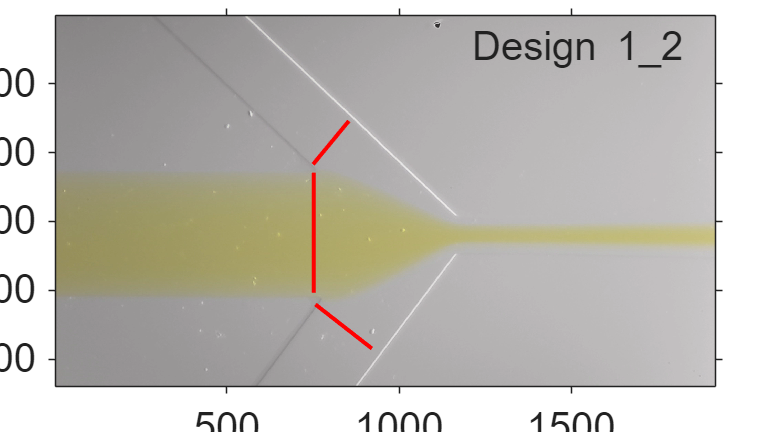

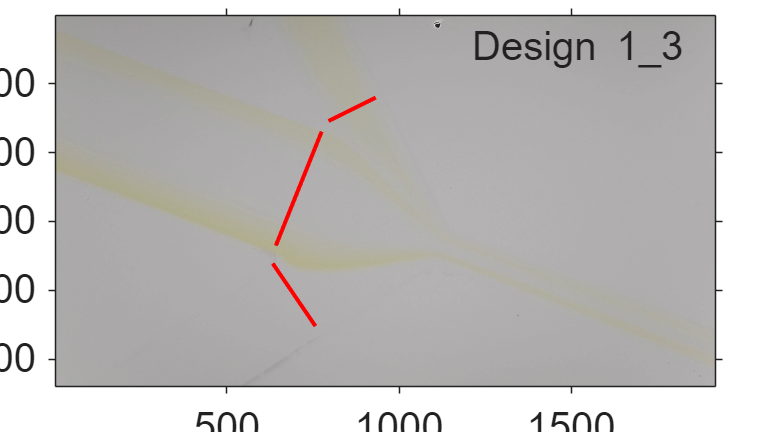

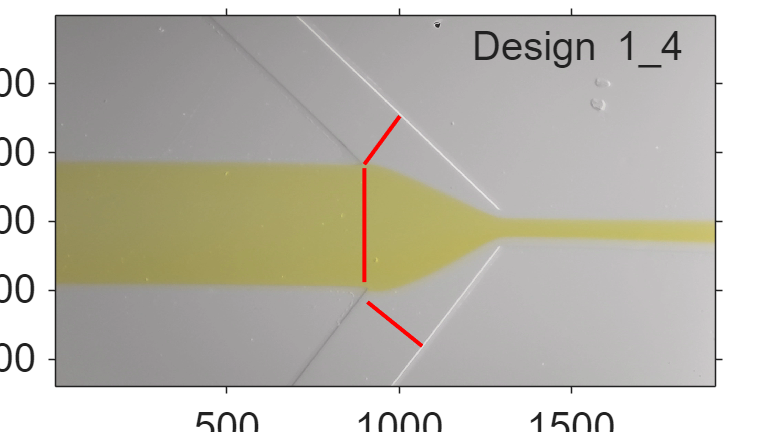

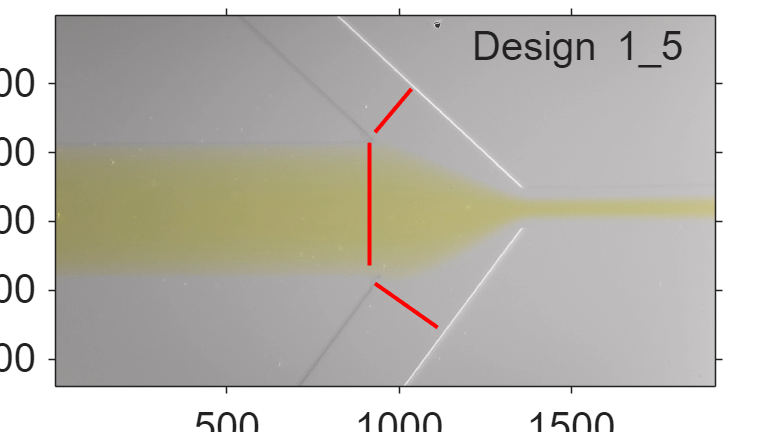


% Predefined coordinates for the line for Design 1_2
xCoords_pipe_1_Design_1_2 = [752, 752]; % X coordinates
yCoords_pipe_1_Design_1_2 = [807, 458]; % Y coordinates
xCoords_pipe_2_Design_1_2 = [750, 854]; % X coordinates
yCoords_pipe_2_Design_1_2 = [434, 308]; % Y coordinates
xCoords_pipe_3_Design_1_2 = [757, 921]; % X coordinates
yCoords_pipe_3_Design_1_2 = [841, 969]; % Y coordinates

% Predefined coordinates for the line for Design 1_3
xCoords_pipe_1_Design_1_3 = [775, 642]; % X coordinates
yCoords_pipe_1_Design_1_3 = [339, 670]; % Y coordinates
xCoords_pipe_2_Design_1_3 = [932, 795]; % X coordinates
yCoords_pipe_2_Design_1_3 = [240, 308]; % Y coordinates
xCoords_pipe_3_Design_1_3 = [633, 757]; % X coordinates
yCoords_pipe_3_Design_1_3 = [722, 904]; % Y coordinates

% Predefined coordinates for the line for Design 1_4
xCoords_pipe_1_Design_1_4 = [899, 899]; % X coordinates
yCoords_pipe_1_Design_1_4 = [445, 776]; % Y coordinates
xCoords_pipe_2_Design_1_4 = [899, 1002]; % X coordinates
yCoords_pipe_2_Design_1_4 = [434, 294]; % Y coordinates
xCoords_pipe_3_Design_1_4 = [908, 1067]; % X coordinates
yCoords_pipe_3_Design_1_4 = [834, 962]; % Y coordinates

% Predefined coordinates for the line for Design 1_5
xCoords_pipe_1_Design_1_5 = [914, 914]; % X coordinates
yCoords_pipe_1_Design_1_5 = [728, 371]; % Y coordinates
xCoords_pipe_2_Design_1_5 = [930, 1036]; % X coordinates
yCoords_pipe_2_Design_1_5 = [341, 215]; % Y coordinates
xCoords_pipe_3_Design_1_5 = [930, 1112]; % X coordinates
yCoords_pipe_3_Design_1_5 = [780, 908]; % Y coordinates

% Plot the first frame of segmentedFrames with axes
if ~isempty(segmentedFrames_Design_1_2)
    figure; % Create a new figure window
    %Design 1_2
    imshow(segmentedFrames_Design_1_2{150}); % Display the first frame
    text(1200,100,"Design 1\_2",FontSize=fontsize);
    axis on; % Turn on the axes
    xlabel('Pixels (X)',Interpreter='latex'); % Label for X-axis
    ylabel('Pixels (Y)',Interpreter='latex'); % Label for Y-axis    
    % Hold the current plot to overlay the line
    hold on;
    plot(xCoords_pipe_1_Design_1_2, yCoords_pipe_1_Design_1_2, 'r-', 'LineWidth', 2); % Plot the line in red with specified width
    plot(xCoords_pipe_2_Design_1_2, yCoords_pipe_2_Design_1_2, 'r-', 'LineWidth', 2); % Plot the line in red with specified width
    plot(xCoords_pipe_3_Design_1_2, yCoords_pipe_3_Design_1_2, 'r-', 'LineWidth', 2); % Plot the line in red with specified width
    hold off;
    set(gca,"FontSize",fontsize)

    %Design 1_3
    figure; % Create a new figure window
    imshow(segmentedFrames_Design_1_3{150}); % Display the first frame
    text(1200,100,"Design 1\_3",FontSize=fontsize);
    axis on; % Turn on the axes
    xlabel('Pixels (X)',Interpreter='latex'); % Label for X-axis
    ylabel('Pixels (Y)',Interpreter='latex'); % Label for Y-axis    
    % Hold the current plot to overlay the line
    hold on;
    plot(xCoords_pipe_1_Design_1_3, yCoords_pipe_1_Design_1_3, 'r-', 'LineWidth', 2); % Plot the line in red with specified width
    plot(xCoords_pipe_2_Design_1_3, yCoords_pipe_2_Design_1_3, 'r-', 'LineWidth', 2); % Plot the line in red with specified width
    plot(xCoords_pipe_3_Design_1_3, yCoords_pipe_3_Design_1_3, 'r-', 'LineWidth', 2); % Plot the line in red with specified width
    hold off;
    set(gca,"FontSize",fontsize)

    %Design 1_4
    figure; % Create a new figure window
    imshow(segmentedFrames_Design_1_4{150}); % Display the first frame
    text(1200,100,"Design 1\_4",FontSize=fontsize);
    axis on; % Turn on the axes
    xlabel('Pixels (X)',Interpreter='latex'); % Label for X-axis
    ylabel('Pixels (Y)',Interpreter='latex'); % Label for Y-axis    
    % Hold the current plot to overlay the line
    hold on;
    plot(xCoords_pipe_1_Design_1_4, yCoords_pipe_1_Design_1_4, 'r-', 'LineWidth', 2); % Plot the line in red with specified width
    plot(xCoords_pipe_2_Design_1_4, yCoords_pipe_2_Design_1_4, 'r-', 'LineWidth', 2); % Plot the line in red with specified width
    plot(xCoords_pipe_3_Design_1_4, yCoords_pipe_3_Design_1_4, 'r-', 'LineWidth', 2); % Plot the line in red with specified width
    hold off;
    set(gca,"FontSize",fontsize)

    %Design 1_5
    figure; % Create a new figure window
    imshow(segmentedFrames_Design_1_5{150}); % Display the first frame
    text(1200,100,"Design 1\_5",FontSize=fontsize);
    axis on; % Turn on the axes
    xlabel('Pixels (X)',Interpreter='latex'); % Label for X-axis
    ylabel('Pixels (Y)',Interpreter='latex'); % Label for Y-axis    
    % Hold the current plot to overlay the line
    hold on;
    plot(xCoords_pipe_1_Design_1_5, yCoords_pipe_1_Design_1_5, 'r-', 'LineWidth', 2); % Plot the line in red with specified width
    plot(xCoords_pipe_2_Design_1_5, yCoords_pipe_2_Design_1_5, 'r-', 'LineWidth', 2); % Plot the line in red with specified width
    plot(xCoords_pipe_3_Design_1_5, yCoords_pipe_3_Design_1_5, 'r-', 'LineWidth', 2); % Plot the line in red with specified width
    hold off;
    set(gca,"FontSize",fontsize)
else
    warning('No frames available to display.');
end

### Intensity at Oulet Pipes 1, 2, and 3

% Initialize an array to store the average intensity values
%Design 1_2
averageIntensities_pipe_1_Design_1_2 = zeros(1, length(segmentedFrames_Design_1_2));
averageIntensities_pipe_2_Design_1_2 = zeros(1, length(segmentedFrames_Design_1_2));
averageIntensities_pipe_3_Design_1_2 = zeros(1, length(segmentedFrames_Design_1_2));

%Design 1_3
averageIntensities_pipe_1_Design_1_3 = zeros(1, length(segmentedFrames_Design_1_3));
averageIntensities_pipe_2_Design_1_3 = zeros(1, length(segmentedFrames_Design_1_3));
averageIntensities_pipe_3_Design_1_3 = zeros(1, length(segmentedFrames_Design_1_3));

%Design 1_4
averageIntensities_pipe_1_Design_1_4 = zeros(1, length(segmentedFrames_Design_1_4));
averageIntensities_pipe_2_Design_1_4 = zeros(1, length(segmentedFrames_Design_1_4));
averageIntensities_pipe_3_Design_1_4 = zeros(1, length(segmentedFrames_Design_1_4));

%Design 1_5
averageIntensities_pipe_1_Design_1_5 = zeros(1, length(segmentedFrames_Design_1_5));
averageIntensities_pipe_2_Design_1_5 = zeros(1, length(segmentedFrames_Design_1_5));
averageIntensities_pipe_3_Design_1_5 = zeros(1, length(segmentedFrames_Design_1_5));

% Loop through each frame to calculate the average intensity along the line
for k = 1:length(segmentedFrames_Design_1_2)

    k/length(segmentedFrames_Design_1_2)*100

    %Design 1_2
    frame = segmentedFrames_Design_1_2{k};
    % Extract the pixel values along the line defined by xCoords and yCoords
    lineProfile_pipe_1 = improfile(frame, xCoords_pipe_1_Design_1_2, yCoords_pipe_1_Design_1_2);
    lineProfile_pipe_2 = improfile(frame, xCoords_pipe_2_Design_1_2, yCoords_pipe_2_Design_1_2);
    lineProfile_pipe_3 = improfile(frame, xCoords_pipe_3_Design_1_2, yCoords_pipe_3_Design_1_2);
    % Calculate the average intensity for the pixels along the line
    averageIntensities_pipe_1_Design_1_2(k) = mean(lineProfile_pipe_1(:));
    averageIntensities_pipe_2_Design_1_2(k) = mean(lineProfile_pipe_2(:));
    averageIntensities_pipe_3_Design_1_2(k) = mean(lineProfile_pipe_3(:));

    %Design 1_3
    frame = segmentedFrames_Design_1_3{k};
    % Extract the pixel values along the line defined by xCoords and yCoords
    lineProfile_pipe_1 = improfile(frame, xCoords_pipe_1_Design_1_3, yCoords_pipe_1_Design_1_3);
    lineProfile_pipe_2 = improfile(frame, xCoords_pipe_2_Design_1_3, yCoords_pipe_2_Design_1_3);
    lineProfile_pipe_3 = improfile(frame, xCoords_pipe_3_Design_1_3, yCoords_pipe_3_Design_1_3);
    % Calculate the average intensity for the pixels along the line
    averageIntensities_pipe_1_Design_1_3(k) = mean(lineProfile_pipe_1(:));
    averageIntensities_pipe_2_Design_1_3(k) = mean(lineProfile_pipe_2(:));
    averageIntensities_pipe_3_Design_1_3(k) = mean(lineProfile_pipe_3(:));

    %Design 1_4
    frame = segmentedFrames_Design_1_4{k};
    % Extract the pixel values along the line defined by xCoords and yCoords
    lineProfile_pipe_1 = improfile(frame, xCoords_pipe_1_Design_1_4, yCoords_pipe_1_Design_1_4);
    lineProfile_pipe_2 = improfile(frame, xCoords_pipe_2_Design_1_4, yCoords_pipe_2_Design_1_4);
    lineProfile_pipe_3 = improfile(frame, xCoords_pipe_3_Design_1_4, yCoords_pipe_3_Design_1_4);
    % Calculate the average intensity for the pixels along the line
    averageIntensities_pipe_1_Design_1_4(k) = mean(lineProfile_pipe_1(:));
    averageIntensities_pipe_2_Design_1_4(k) = mean(lineProfile_pipe_2(:));
    averageIntensities_pipe_3_Design_1_4(k) = mean(lineProfile_pipe_3(:));

    %Design 1_5
    frame = segmentedFrames_Design_1_5{k};
    % Extract the pixel values along the line defined by xCoords and yCoords
    lineProfile_pipe_1 = improfile(frame, xCoords_pipe_1_Design_1_5, yCoords_pipe_1_Design_1_5);
    lineProfile_pipe_2 = improfile(frame, xCoords_pipe_2_Design_1_5, yCoords_pipe_2_Design_1_5);
    lineProfile_pipe_3 = improfile(frame, xCoords_pipe_3_Design_1_5, yCoords_pipe_3_Design_1_5);
    % Calculate the average intensity for the pixels along the line
    averageIntensities_pipe_1_Design_1_5(k) = mean(lineProfile_pipe_1(:));
    averageIntensities_pipe_2_Design_1_5(k) = mean(lineProfile_pipe_2(:));
    averageIntensities_pipe_3_Design_1_5(k) = mean(lineProfile_pipe_3(:));
end

ans = 0.1189

ans = 0.2378

ans = 0.3567

ans = 0.4756

ans = 0.5945

ans = 0.7134

ans = 0.8323

ans = 0.9512

ans = 1.0702

ans = 1.1891

ans = 1.3080

ans = 1.4269

ans = 1.5458

ans = 1.6647

ans = 1.7836

ans = 1.9025

ans = 2.0214

ans = 2.1403

ans = 2.2592

ans = 2.3781

ans = 2.4970

ans = 2.6159

ans = 2.7348

ans = 2.8537

ans = 2.9727

ans = 3.0916

ans = 3.2105

ans = 3.3294

ans = 3.4483

ans = 3.5672

ans = 3.6861

ans = 3.8050

ans = 3.9239

ans = 4.0428

ans = 4.1617

ans = 4.2806

ans = 4.3995

ans = 4.5184

ans = 4.6373

ans = 4.7562

ans = 4.8751

ans = 4.9941

ans = 5.1130

ans = 5.2319

ans = 5.3508

ans = 5.4697

ans = 5.5886

ans = 5.7075

ans = 5.8264

ans = 5.9453

ans = 6.0642

ans = 6.1831

ans = 6.3020

ans = 6.4209

ans = 6.5398

ans = 6.6587

ans = 6.7776

ans = 6.8966

ans = 7.0155

ans = 7.1344

ans = 7.2533

ans = 7.3722

ans = 7.4911

ans = 7.6100

ans = 7.7289

ans = 7.8478

ans = 7.9667

ans = 8.0856

ans = 8.2045

ans = 8.3234

ans = 8.4423

ans = 8.5612

ans = 8.6801

ans = 8.7990

ans = 8.9180

ans = 9.0369

ans = 9.1558

ans = 9.2747

ans = 9.3936

ans = 9.5125

ans = 9.6314

ans = 9.7503

ans = 9.8692

ans = 9.9881

ans = 10.1070

ans = 10.2259

ans = 10.3448

ans = 10.4637

ans = 10.5826

ans = 10.7015

ans = 10.8205

ans = 10.9394

ans = 11.0583

ans = 11.1772

ans = 11.2961

ans = 11.4150

ans = 11.5339

ans = 11.6528

ans = 11.7717

ans = 11.8906

ans = 12.0095

ans = 12.1284

ans = 12.2473

ans = 12.3662

ans = 12.4851

ans = 12.6040

ans = 12.7229

ans = 12.8419

ans = 12.9608

ans = 13.0797

ans = 13.1986

ans = 13.3175

ans = 13.4364

ans = 13.5553

ans = 13.6742

ans = 13.7931

ans = 13.9120

ans = 14.0309

ans = 14.1498

ans = 14.2687

ans = 14.3876

ans = 14.5065

ans = 14.6254

ans = 14.7444

ans = 14.8633

ans = 14.9822

ans = 15.1011

ans = 15.2200

ans = 15.3389

ans = 15.4578

ans = 15.5767

ans = 15.6956

ans = 15.8145

ans = 15.9334

ans = 16.0523

ans = 16.1712

ans = 16.2901

ans = 16.4090

ans = 16.5279

ans = 16.6468

ans = 16.7658

ans = 16.8847

ans = 17.0036

ans = 17.1225

ans = 17.2414

ans = 17.3603

ans = 17.4792

ans = 17.5981

ans = 17.7170

ans = 17.8359

ans = 17.9548

ans = 18.0737

ans = 18.1926

ans = 18.3115

ans = 18.4304

ans = 18.5493

ans = 18.6683

ans = 18.7872

ans = 18.9061

ans = 19.0250

ans = 19.1439

ans = 19.2628

ans = 19.3817

ans = 19.5006

ans = 19.6195

ans = 19.7384

ans = 19.8573

ans = 19.9762

ans = 20.0951

ans = 20.2140

ans = 20.3329

ans = 20.4518

ans = 20.5707

ans = 20.6897

ans = 20.8086

ans = 20.9275

ans = 21.0464

ans = 21.1653

ans = 21.2842

ans = 21.4031

ans = 21.5220

ans = 21.6409

ans = 21.7598

ans = 21.8787

ans = 21.9976

ans = 22.1165

ans = 22.2354

ans = 22.3543

ans = 22.4732

ans = 22.5922

ans = 22.7111

ans = 22.8300

ans = 22.9489

ans = 23.0678

ans = 23.1867

ans = 23.3056

ans = 23.4245

ans = 23.5434

ans = 23.6623

ans = 23.7812

ans = 23.9001

ans = 24.0190

ans = 24.1379

ans = 24.2568

ans = 24.3757

ans = 24.4946

ans = 24.6136

ans = 24.7325

ans = 24.8514

ans = 24.9703

ans = 25.0892

ans = 25.2081

ans = 25.3270

ans = 25.4459

ans = 25.5648

ans = 25.6837

ans = 25.8026

ans = 25.9215

ans = 26.0404

ans = 26.1593

ans = 26.2782

ans = 26.3971

ans = 26.5161

ans = 26.6350

ans = 26.7539

ans = 26.8728

ans = 26.9917

ans = 27.1106

ans = 27.2295

ans = 27.3484

ans = 27.4673

ans = 27.5862

ans = 27.7051

ans = 27.8240

ans = 27.9429

ans = 28.0618

ans = 28.1807

ans = 28.2996

ans = 28.4185

ans = 28.5375

ans = 28.6564

ans = 28.7753

ans = 28.8942

ans = 29.0131

ans = 29.1320

ans = 29.2509

ans = 29.3698

ans = 29.4887

ans = 29.6076

ans = 29.7265

ans = 29.8454

ans = 29.9643

ans = 30.0832

ans = 30.2021

ans = 30.3210

ans = 30.4400

ans = 30.5589

ans = 30.6778

ans = 30.7967

ans = 30.9156

ans = 31.0345

ans = 31.1534

ans = 31.2723

ans = 31.3912

ans = 31.5101

ans = 31.6290

ans = 31.7479

ans = 31.8668

ans = 31.9857

ans = 32.1046

ans = 32.2235

ans = 32.3424

ans = 32.4614

ans = 32.5803

ans = 32.6992

ans = 32.8181

ans = 32.9370

ans = 33.0559

ans = 33.1748

ans = 33.2937

ans = 33.4126

ans = 33.5315

ans = 33.6504

ans = 33.7693

ans = 33.8882

ans = 34.0071

ans = 34.1260

ans = 34.2449

ans = 34.3639

ans = 34.4828

ans = 34.6017

ans = 34.7206

ans = 34.8395

ans = 34.9584

ans = 35.0773

ans = 35.1962

ans = 35.3151

ans = 35.4340

ans = 35.5529

ans = 35.6718

ans = 35.7907

ans = 35.9096

ans = 36.0285

ans = 36.1474

ans = 36.2663

ans = 36.3853

ans = 36.5042

ans = 36.6231

ans = 36.7420

ans = 36.8609

ans = 36.9798

ans = 37.0987

ans = 37.2176

ans = 37.3365

ans = 37.4554

ans = 37.5743

ans = 37.6932

ans = 37.8121

ans = 37.9310

ans = 38.0499

ans = 38.1688

ans = 38.2878

ans = 38.4067

ans = 38.5256

ans = 38.6445

ans = 38.7634

ans = 38.8823

ans = 39.0012

ans = 39.1201

ans = 39.2390

ans = 39.3579

ans = 39.4768

ans = 39.5957

ans = 39.7146

ans = 39.8335

ans = 39.9524

ans = 40.0713

ans = 40.1902

ans = 40.3092

ans = 40.4281

ans = 40.5470

ans = 40.6659

ans = 40.7848

ans = 40.9037

ans = 41.0226

ans = 41.1415

ans = 41.2604

ans = 41.3793

ans = 41.4982

ans = 41.6171

ans = 41.7360

ans = 41.8549

ans = 41.9738

ans = 42.0927

ans = 42.2117

ans = 42.3306

ans = 42.4495

ans = 42.5684

ans = 42.6873

ans = 42.8062

ans = 42.9251

ans = 43.0440

ans = 43.1629

ans = 43.2818

ans = 43.4007

ans = 43.5196

ans = 43.6385

ans = 43.7574

ans = 43.8763

ans = 43.9952

ans = 44.1141

ans = 44.2331

ans = 44.3520

ans = 44.4709

ans = 44.5898

ans = 44.7087

ans = 44.8276

ans = 44.9465

ans = 45.0654

ans = 45.1843

ans = 45.3032

ans = 45.4221

ans = 45.5410

ans = 45.6599

ans = 45.7788

ans = 45.8977

ans = 46.0166

ans = 46.1356

ans = 46.2545

ans = 46.3734

ans = 46.4923

ans = 46.6112

ans = 46.7301

ans = 46.8490

ans = 46.9679

ans = 47.0868

ans = 47.2057

ans = 47.3246

ans = 47.4435

ans = 47.5624

ans = 47.6813

ans = 47.8002

ans = 47.9191

ans = 48.0380

ans = 48.1570

ans = 48.2759

ans = 48.3948

ans = 48.5137

ans = 48.6326

ans = 48.7515

ans = 48.8704

ans = 48.9893

ans = 49.1082

ans = 49.2271

ans = 49.3460

ans = 49.4649

ans = 49.5838

ans = 49.7027

ans = 49.8216

ans = 49.9405

ans = 50.0595

ans = 50.1784

ans = 50.2973

ans = 50.4162

ans = 50.5351

ans = 50.6540

ans = 50.7729

ans = 50.8918

ans = 51.0107

ans = 51.1296

ans = 51.2485

ans = 51.3674

ans = 51.4863

ans = 51.6052

ans = 51.7241

ans = 51.8430

ans = 51.9620

ans = 52.0809

ans = 52.1998

ans = 52.3187

ans = 52.4376

ans = 52.5565

ans = 52.6754

ans = 52.7943

ans = 52.9132

ans = 53.0321

ans = 53.1510

ans = 53.2699

ans = 53.3888

ans = 53.5077

ans = 53.6266

ans = 53.7455

ans = 53.8644

ans = 53.9834

ans = 54.1023

ans = 54.2212

ans = 54.3401

ans = 54.4590

ans = 54.5779

ans = 54.6968

ans = 54.8157

ans = 54.9346

ans = 55.0535

ans = 55.1724

ans = 55.2913

ans = 55.4102

ans = 55.5291

ans = 55.6480

ans = 55.7669

ans = 55.8859

ans = 56.0048

ans = 56.1237

ans = 56.2426

ans = 56.3615

ans = 56.4804

ans = 56.5993

ans = 56.7182

ans = 56.8371

ans = 56.9560

ans = 57.0749

ans = 57.1938

ans = 57.3127

ans = 57.4316

ans = 57.5505

ans = 57.6694

ans = 57.7883

ans = 57.9073

ans = 58.0262

ans = 58.1451

ans = 58.2640

ans = 58.3829

ans = 58.5018

ans = 58.6207

ans = 58.7396

ans = 58.8585

ans = 58.9774

ans = 59.0963

ans = 59.2152

ans = 59.3341

ans = 59.4530

ans = 59.5719

ans = 59.6908

ans = 59.8098

ans = 59.9287

ans = 60.0476

ans = 60.1665

ans = 60.2854

ans = 60.4043

ans = 60.5232

ans = 60.6421

ans = 60.7610

ans = 60.8799

ans = 60.9988

ans = 61.1177

ans = 61.2366

ans = 61.3555

ans = 61.4744

ans = 61.5933

ans = 61.7122

ans = 61.8312

ans = 61.9501

ans = 62.0690

ans = 62.1879

ans = 62.3068

ans = 62.4257

ans = 62.5446

ans = 62.6635

ans = 62.7824

ans = 62.9013

ans = 63.0202

ans = 63.1391

ans = 63.2580

ans = 63.3769

ans = 63.4958

ans = 63.6147

ans = 63.7337

ans = 63.8526

ans = 63.9715

ans = 64.0904

ans = 64.2093

ans = 64.3282

ans = 64.4471

ans = 64.5660

ans = 64.6849

ans = 64.8038

ans = 64.9227

ans = 65.0416

ans = 65.1605

ans = 65.2794

ans = 65.3983

ans = 65.5172

ans = 65.6361

ans = 65.7551

ans = 65.8740

ans = 65.9929

ans = 66.1118

ans = 66.2307

ans = 66.3496

ans = 66.4685

ans = 66.5874

ans = 66.7063

ans = 66.8252

ans = 66.9441

ans = 67.0630

ans = 67.1819

ans = 67.3008

ans = 67.4197

ans = 67.5386

ans = 67.6576

ans = 67.7765

ans = 67.8954

ans = 68.0143

ans = 68.1332

ans = 68.2521

ans = 68.3710

ans = 68.4899

ans = 68.6088

ans = 68.7277

ans = 68.8466

ans = 68.9655

ans = 69.0844

ans = 69.2033

ans = 69.3222

ans = 69.4411

ans = 69.5600

ans = 69.6790

ans = 69.7979

ans = 69.9168

ans = 70.0357

ans = 70.1546

ans = 70.2735

ans = 70.3924

ans = 70.5113

ans = 70.6302

ans = 70.7491

ans = 70.8680

ans = 70.9869

ans = 71.1058

ans = 71.2247

ans = 71.3436

ans = 71.4625

ans = 71.5815

ans = 71.7004

ans = 71.8193

ans = 71.9382

ans = 72.0571

ans = 72.1760

ans = 72.2949

ans = 72.4138

ans = 72.5327

ans = 72.6516

ans = 72.7705

ans = 72.8894

ans = 73.0083

ans = 73.1272

ans = 73.2461

ans = 73.3650

ans = 73.4839

ans = 73.6029

ans = 73.7218

ans = 73.8407

ans = 73.9596

ans = 74.0785

ans = 74.1974

ans = 74.3163

ans = 74.4352

ans = 74.5541

ans = 74.6730

ans = 74.7919

ans = 74.9108

ans = 75.0297

ans = 75.1486

ans = 75.2675

ans = 75.3864

ans = 75.5054

ans = 75.6243

ans = 75.7432

ans = 75.8621

ans = 75.9810

ans = 76.0999

ans = 76.2188

ans = 76.3377

ans = 76.4566

ans = 76.5755

ans = 76.6944

ans = 76.8133

ans = 76.9322

ans = 77.0511

ans = 77.1700

ans = 77.2889

ans = 77.4078

ans = 77.5268

ans = 77.6457

ans = 77.7646

ans = 77.8835

ans = 78.0024

ans = 78.1213

ans = 78.2402

ans = 78.3591

ans = 78.4780

ans = 78.5969

ans = 78.7158

ans = 78.8347

ans = 78.9536

ans = 79.0725

ans = 79.1914

ans = 79.3103

ans = 79.4293

ans = 79.5482

ans = 79.6671

ans = 79.7860

ans = 79.9049

ans = 80.0238

ans = 80.1427

ans = 80.2616

ans = 80.3805

ans = 80.4994

ans = 80.6183

ans = 80.7372

ans = 80.8561

ans = 80.9750

ans = 81.0939

ans = 81.2128

ans = 81.3317

ans = 81.4507

ans = 81.5696

ans = 81.6885

ans = 81.8074

ans = 81.9263

ans = 82.0452

ans = 82.1641

ans = 82.2830

ans = 82.4019

ans = 82.5208

ans = 82.6397

ans = 82.7586

ans = 82.8775

ans = 82.9964

ans = 83.1153

ans = 83.2342

ans = 83.3532

ans = 83.4721

ans = 83.5910

ans = 83.7099

ans = 83.8288

ans = 83.9477

ans = 84.0666

ans = 84.1855

ans = 84.3044

ans = 84.4233

ans = 84.5422

ans = 84.6611

ans = 84.7800

ans = 84.8989

ans = 85.0178

ans = 85.1367

ans = 85.2556

ans = 85.3746

ans = 85.4935

ans = 85.6124

ans = 85.7313

ans = 85.8502

ans = 85.9691

ans = 86.0880

ans = 86.2069

ans = 86.3258

ans = 86.4447

ans = 86.5636

ans = 86.6825

ans = 86.8014

ans = 86.9203

ans = 87.0392

ans = 87.1581

ans = 87.2771

ans = 87.3960

ans = 87.5149

ans = 87.6338

ans = 87.7527

ans = 87.8716

ans = 87.9905

ans = 88.1094

ans = 88.2283

ans = 88.3472

ans = 88.4661

ans = 88.5850

ans = 88.7039

ans = 88.8228

ans = 88.9417

ans = 89.0606

ans = 89.1795

ans = 89.2985

ans = 89.4174

ans = 89.5363

ans = 89.6552

ans = 89.7741

ans = 89.8930

ans = 90.0119

ans = 90.1308

ans = 90.2497

ans = 90.3686

ans = 90.4875

ans = 90.6064

ans = 90.7253

ans = 90.8442

ans = 90.9631

ans = 91.0820

ans = 91.2010

ans = 91.3199

ans = 91.4388

ans = 91.5577

ans = 91.6766

ans = 91.7955

ans = 91.9144

ans = 92.0333

ans = 92.1522

ans = 92.2711

ans = 92.3900

ans = 92.5089

ans = 92.6278

ans = 92.7467

ans = 92.8656

ans = 92.9845

ans = 93.1034

ans = 93.2224

ans = 93.3413

ans = 93.4602

ans = 93.5791

ans = 93.6980

ans = 93.8169

ans = 93.9358

ans = 94.0547

ans = 94.1736

ans = 94.2925

ans = 94.4114

ans = 94.5303

ans = 94.6492

ans = 94.7681

ans = 94.8870

ans = 95.0059

ans = 95.1249

ans = 95.2438

ans = 95.3627

ans = 95.4816

ans = 95.6005

ans = 95.7194

ans = 95.8383

ans = 95.9572

ans = 96.0761

ans = 96.1950

ans = 96.3139

ans = 96.4328

ans = 96.5517

ans = 96.6706

ans = 96.7895

ans = 96.9084

ans = 97.0273

ans = 97.1463

ans = 97.2652

ans = 97.3841

ans = 97.5030

ans = 97.6219

ans = 97.7408

ans = 97.8597

ans = 97.9786

ans = 98.0975

ans = 98.2164

ans = 98.3353

ans = 98.4542

ans = 98.5731

ans = 98.6920

ans = 98.8109

ans = 98.9298

ans = 99.0488

ans = 99.1677

ans = 99.2866

ans = 99.4055

ans = 99.5244

ans = 99.6433

ans = 99.7622

ans = 99.8811

ans = 100


% %Swapping the values of averageIntensities around its maximum 
% max_averageIntensities=max(averageIntensities_pipe_1);
% averageIntensities_swap_pipe_1=-(averageIntensities_pipe_1-max_averageIntensities);
% 
% max_averageIntensities=max(averageIntensities_pipe_2);
% averageIntensities_swap_pipe_2=-(averageIntensities_pipe_2-max_averageIntensities);
% 
% max_averageIntensities=max(averageIntensities_pipe_3);
% averageIntensities_swap_pipe_3=-(averageIntensities_pipe_3-max_averageIntensities);

%Concentration of Tartrazine
%Design_1_1
k=10*log10(mean(averageIntensities_Tx_Design_1_2))/c_max;%conversion rate from intensity to concentration
A_0=min(-10*log10(averageIntensities_pipe_1_Design_1_2));
A_1=min(-10*log10(averageIntensities_pipe_2_Design_1_2));
A_2=min(-10*log10(averageIntensities_pipe_3_Design_1_2));

conc_Pipe_1_Exp_Design_1_2=(-10*log10(averageIntensities_pipe_1_Design_1_2)-A_0)/k;
conc_Pipe_2_Exp_Design_1_2=(-10*log10(averageIntensities_pipe_2_Design_1_2)-A_0)/k;
conc_Pipe_3_Exp_Design_1_2=(-10*log10(averageIntensities_pipe_3_Design_1_2)-A_0)/k;

%Design_1_3
A_0_3=min(-10*log10(averageIntensities_pipe_1_Design_1_3));
A_1_3=min(-10*log10(averageIntensities_pipe_2_Design_1_3));
A_2_3=min(-10*log10(averageIntensities_pipe_3_Design_1_3));

conc_Pipe_1_Exp_Design_1_3=(-10*log10(averageIntensities_pipe_1_Design_1_3)-A_0_3)/k;
conc_Pipe_2_Exp_Design_1_3=(-10*log10(averageIntensities_pipe_2_Design_1_3)-A_0_3)/k;
conc_Pipe_3_Exp_Design_1_3=(-10*log10(averageIntensities_pipe_3_Design_1_3)-A_0_3)/k;

%Design_1_4
A_0_4=min(-10*log10(averageIntensities_pipe_1_Design_1_4));
A_1_4=min(-10*log10(averageIntensities_pipe_2_Design_1_4));
A_2_4=min(-10*log10(averageIntensities_pipe_3_Design_1_4));

conc_Pipe_1_Exp_Design_1_4=(-10*log10(averageIntensities_pipe_1_Design_1_4)-A_0_4)/k;
conc_Pipe_2_Exp_Design_1_4=(-10*log10(averageIntensities_pipe_2_Design_1_4)-A_0_4)/k;
conc_Pipe_3_Exp_Design_1_4=(-10*log10(averageIntensities_pipe_3_Design_1_4)-A_0_4)/k;

%Design_1_5
A_0_5=min(-10*log10(averageIntensities_pipe_1_Design_1_5));
A_1_5=min(-10*log10(averageIntensities_pipe_2_Design_1_5));
A_2_5=min(-10*log10(averageIntensities_pipe_3_Design_1_5));

conc_Pipe_1_Exp_Design_1_5=(-10*log10(averageIntensities_pipe_1_Design_1_5)-A_0_5)/k;
conc_Pipe_2_Exp_Design_1_5=(-10*log10(averageIntensities_pipe_2_Design_1_5)-A_0_5)/k;
conc_Pipe_3_Exp_Design_1_5=(-10*log10(averageIntensities_pipe_3_Design_1_5)-A_0_5)/k;



#### Evaluating the maximum of the three pipes

timeVector = linspace(startTime_Outlet_CNN, endTime_Outlet_CNN, length(conc_Pipe_1_Exp_Design_1_2)); % Create a time vector

%Evaluating the peaks
%Design 1_2
[peak_1_Exp_Design_1_2,idx]=max(conc_Pipe_1_Exp_Design_1_2);
tau_1_Exp_Design_1_2=timeVector(idx);
[peak_2_Exp_Design_1_2,idx]=max(conc_Pipe_2_Exp_Design_1_2);
tau_2_Exp_Design_1_2=timeVector(idx);
[peak_3_Exp_Design_1_2,idx]=max(conc_Pipe_3_Exp_Design_1_2);
tau_3_Exp_Design_1_2=timeVector(idx);

%Design 1_3
[peak_1_Exp_Design_1_3,idx]=max(conc_Pipe_1_Exp_Design_1_3);
tau_1_Exp_Design_1_3=timeVector(idx);
[peak_2_Exp_Design_1_3,idx]=max(conc_Pipe_2_Exp_Design_1_3);
tau_2_Exp_Design_1_3=timeVector(idx);
[peak_3_Exp_Design_1_3,idx]=max(conc_Pipe_3_Exp_Design_1_3);
tau_3_Exp_Design_1_3=timeVector(idx);

%Design 1_4
[peak_1_Exp_Design_1_4,idx]=max(conc_Pipe_1_Exp_Design_1_4);
tau_1_Exp_Design_1_4=timeVector(idx);
[peak_2_Exp_Design_1_4,idx]=max(conc_Pipe_2_Exp_Design_1_4);
tau_2_Exp_Design_1_4=timeVector(idx);
[peak_3_Exp_Design_1_4,idx]=max(conc_Pipe_3_Exp_Design_1_4);
tau_3_Exp_Design_1_4=timeVector(idx);

%Design 1_5
[peak_1_Exp_Design_1_5,idx]=max(conc_Pipe_1_Exp_Design_1_5);
tau_1_Exp_Design_1_5=timeVector(idx);
[peak_2_Exp_Design_1_5,idx]=max(conc_Pipe_2_Exp_Design_1_5);
tau_2_Exp_Design_1_5=timeVector(idx);
[peak_3_Exp_Design_1_5,idx]=max(conc_Pipe_3_Exp_Design_1_5);
tau_3_Exp_Design_1_5=timeVector(idx);


### Plot  Experimental Concentration

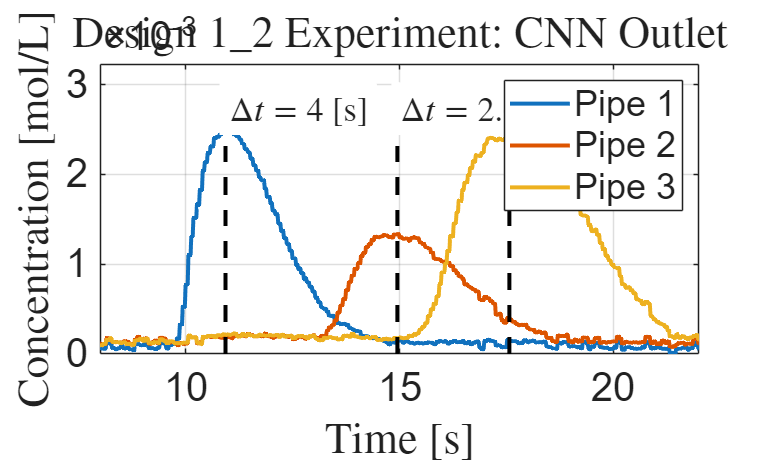

%Design 1_1
figure; % Plotting the concentration with time
plot(timeVector, conc_Pipe_1_Exp_Design_1_2, 'LineWidth', 2); hold on; % Plot average intensities with blue line and circle markers
plot(timeVector, conc_Pipe_2_Exp_Design_1_2, 'LineWidth', 2); % Plot average intensities with blue line and circle markers
plot(timeVector, conc_Pipe_3_Exp_Design_1_2, 'LineWidth', 2); % Plot average intensities with blue line and circle markers
% Plotting the maximum
max_intensity=max([max(conc_Pipe_1_Exp_Design_1_2),max(conc_Pipe_2_Exp_Design_1_2),max(conc_Pipe_3_Exp_Design_1_2)]);
plot([tau_1_Exp_Design_1_2 tau_1_Exp_Design_1_2],[0 1.1*max_intensity],'--k',LineWidth=2);
plot([tau_2_Exp_Design_1_2 tau_2_Exp_Design_1_2],[0 1.1*max_intensity],'--k',LineWidth=2);
plot([tau_3_Exp_Design_1_2 tau_3_Exp_Design_1_2],[0 1.1*max_intensity],'--k',LineWidth=2);
text(tau_1_Exp_Design_1_2,1.1*max_intensity,strcat('$\Delta t=',num2str(tau_2_Exp_Design_1_2-tau_1_Exp_Design_1_2,2),'$ [s]'),Interpreter='latex',FontSize=fontsize-3,BackgroundColor='w');
text(tau_2_Exp_Design_1_2,1.1*max_intensity,strcat('$\Delta t=',num2str(tau_3_Exp_Design_1_2-tau_2_Exp_Design_1_2,2),'$ [s]'),Interpreter='latex',FontSize=fontsize-3,BackgroundColor='w');
xlabel('Time [s]', 'Interpreter', 'latex'); % Label for X-axis
ylabel('Concentration [mol/L]', 'Interpreter', 'latex'); % Label for Y-axis
title('Design 1\_2 Experiment: CNN Outlet', 'Interpreter', 'latex'); % Title of the plot
legend("Pipe 1","Pipe 2","Pipe 3");
grid on; % Turn on the grid
axis([timeVector(1) timeVector(end) 0 1.3*max_intensity]);
set(gca, 'FontSize', fontsize); % Set font size for axes

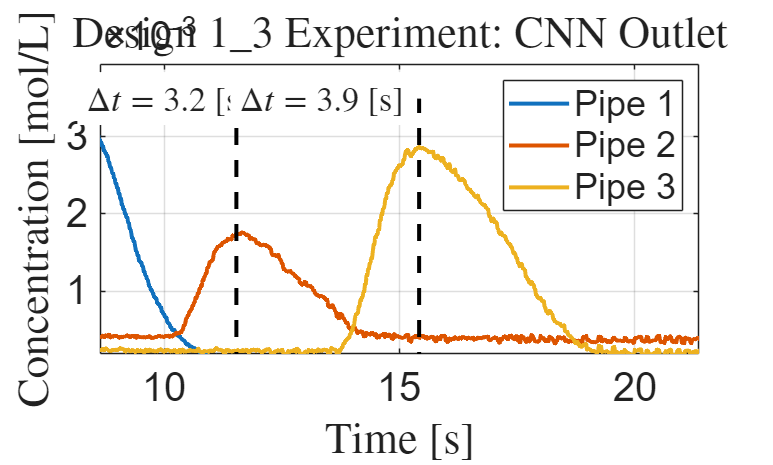


%Design 1_3
figure; % Plotting the concentration with time
plot(timeVector, conc_Pipe_1_Exp_Design_1_3, 'LineWidth', 2); hold on; % Plot average intensities with blue line and circle markers
plot(timeVector, conc_Pipe_2_Exp_Design_1_3, 'LineWidth', 2); % Plot average intensities with blue line and circle markers
plot(timeVector, conc_Pipe_3_Exp_Design_1_3, 'LineWidth', 2); % Plot average intensities with blue line and circle markers
% Plotting the maximum
max_intensity=max([max(conc_Pipe_1_Exp_Design_1_3),max(conc_Pipe_2_Exp_Design_1_3),max(conc_Pipe_3_Exp_Design_1_3)]);
plot([tau_1_Exp_Design_1_3 tau_1_Exp_Design_1_3],[0 1.1*max_intensity],'--k',LineWidth=2);
plot([tau_2_Exp_Design_1_3 tau_2_Exp_Design_1_3],[0 1.1*max_intensity],'--k',LineWidth=2);
plot([tau_3_Exp_Design_1_3 tau_3_Exp_Design_1_3],[0 1.1*max_intensity],'--k',LineWidth=2);
text(tau_1_Exp_Design_1_3,1.1*max_intensity,strcat('$\Delta t=',num2str(tau_2_Exp_Design_1_3-tau_1_Exp_Design_1_3,2),'$ [s]'),Interpreter='latex',FontSize=fontsize-3,BackgroundColor='w');
text(tau_2_Exp_Design_1_3,1.1*max_intensity,strcat('$\Delta t=',num2str(tau_3_Exp_Design_1_3-tau_2_Exp_Design_1_3,2),'$ [s]'),Interpreter='latex',FontSize=fontsize-3,BackgroundColor='w');
xlabel('Time [s]', 'Interpreter', 'latex'); % Label for X-axis
ylabel('Concentration [mol/L]', 'Interpreter', 'latex'); % Label for Y-axis
title('Design 1\_3 Experiment: CNN Outlet', 'Interpreter', 'latex'); % Title of the plot
legend("Pipe 1","Pipe 2","Pipe 3");
grid on; % Turn on the grid
axis([timeVector(1) timeVector(end) 0 1.3*max_intensity]);
set(gca, 'FontSize', fontsize); % Set font size for axes

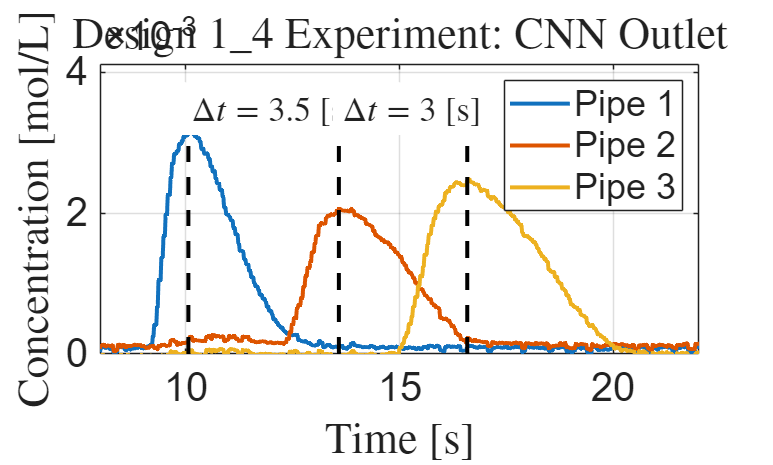


%Design 1_4
figure; % Plotting the concentration with time
plot(timeVector, conc_Pipe_1_Exp_Design_1_4, 'LineWidth', 2); hold on; % Plot average intensities with blue line and circle markers
plot(timeVector, conc_Pipe_2_Exp_Design_1_4, 'LineWidth', 2); % Plot average intensities with blue line and circle markers
plot(timeVector, conc_Pipe_3_Exp_Design_1_4, 'LineWidth', 2); % Plot average intensities with blue line and circle markers
% Plotting the maximum
max_intensity=max([max(conc_Pipe_1_Exp_Design_1_4),max(conc_Pipe_2_Exp_Design_1_4),max(conc_Pipe_3_Exp_Design_1_4)]);
plot([tau_1_Exp_Design_1_4 tau_1_Exp_Design_1_4],[0 1.1*max_intensity],'--k',LineWidth=2);
plot([tau_2_Exp_Design_1_4 tau_2_Exp_Design_1_4],[0 1.1*max_intensity],'--k',LineWidth=2);
plot([tau_3_Exp_Design_1_4 tau_3_Exp_Design_1_4],[0 1.1*max_intensity],'--k',LineWidth=2);
text(tau_1_Exp_Design_1_4,1.1*max_intensity,strcat('$\Delta t=',num2str(tau_2_Exp_Design_1_4-tau_1_Exp_Design_1_4,2),'$ [s]'),Interpreter='latex',FontSize=fontsize-3,BackgroundColor='w');
text(tau_2_Exp_Design_1_4,1.1*max_intensity,strcat('$\Delta t=',num2str(tau_3_Exp_Design_1_4-tau_2_Exp_Design_1_4,2),'$ [s]'),Interpreter='latex',FontSize=fontsize-3,BackgroundColor='w');
xlabel('Time [s]', 'Interpreter', 'latex'); % Label for X-axis
ylabel('Concentration [mol/L]', 'Interpreter', 'latex'); % Label for Y-axis
title('Design 1\_4 Experiment: CNN Outlet', 'Interpreter', 'latex'); % Title of the plot
legend("Pipe 1","Pipe 2","Pipe 3");
grid on; % Turn on the grid
axis([timeVector(1) timeVector(end) 0 1.3*max_intensity]);
set(gca, 'FontSize', fontsize); % Set font size for axes

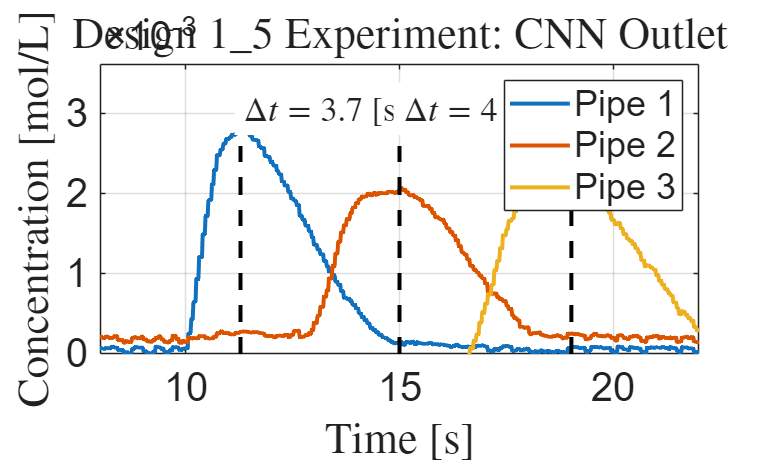


%Design 1_5
figure; % Plotting the concentration with time
plot(timeVector, conc_Pipe_1_Exp_Design_1_5, 'LineWidth', 2); hold on; % Plot average intensities with blue line and circle markers
plot(timeVector, conc_Pipe_2_Exp_Design_1_5, 'LineWidth', 2); % Plot average intensities with blue line and circle markers
plot(timeVector, conc_Pipe_3_Exp_Design_1_5, 'LineWidth', 2); % Plot average intensities with blue line and circle markers
% Plotting the maximum
max_intensity=max([max(conc_Pipe_1_Exp_Design_1_5),max(conc_Pipe_2_Exp_Design_1_5),max(conc_Pipe_3_Exp_Design_1_5)]);
plot([tau_1_Exp_Design_1_5 tau_1_Exp_Design_1_5],[0 1.1*max_intensity],'--k',LineWidth=2);
plot([tau_2_Exp_Design_1_5 tau_2_Exp_Design_1_5],[0 1.1*max_intensity],'--k',LineWidth=2);
plot([tau_3_Exp_Design_1_5 tau_3_Exp_Design_1_5],[0 1.1*max_intensity],'--k',LineWidth=2);
text(tau_1_Exp_Design_1_5,1.1*max_intensity,strcat('$\Delta t=',num2str(tau_2_Exp_Design_1_5-tau_1_Exp_Design_1_5,2),'$ [s]'),Interpreter='latex',FontSize=fontsize-3,BackgroundColor='w');
text(tau_2_Exp_Design_1_5,1.1*max_intensity,strcat('$\Delta t=',num2str(tau_3_Exp_Design_1_5-tau_2_Exp_Design_1_5,2),'$ [s]'),Interpreter='latex',FontSize=fontsize-3,BackgroundColor='w');
xlabel('Time [s]', 'Interpreter', 'latex'); % Label for X-axis
ylabel('Concentration [mol/L]', 'Interpreter', 'latex'); % Label for Y-axis
title('Design 1\_5 Experiment: CNN Outlet', 'Interpreter', 'latex'); % Title of the plot
legend("Pipe 1","Pipe 2","Pipe 3");
grid on; % Turn on the grid
axis([timeVector(1) timeVector(end) 0 1.3*max_intensity]);
set(gca, 'FontSize', fontsize); % Set font size for axes

#### COMSOL Phase 1

%Pipe 1
% Specify the MAT file for the parameters
csvFileName = '3D_Pipe_1_Outlet_Concentration_Surface_Average_COMSOL_3D_CNN_Design_1_2.csv';
%entry from the table
opts=detectImportOptions(csvFileName,'ReadVariableNames', false);
% preview(csvFileName,opts) %data file preview
table=readtable(csvFileName,opts);
time=table.Var1;
%concentration
conc_Pipe_1_COMSOL=table.Var2;
%CIR
h_cir_1_COMSOL=gradient(conc_Pipe_1_COMSOL,time);

%Pipe 2
% Specify the MAT file for the parameters
csvFileName = '3D_Pipe_2_Outlet_Concentration_Surface_Average_COMSOL_3D_CNN_Design_1_2.csv';
%entry from the table
opts=detectImportOptions(csvFileName,'ReadVariableNames', false);
% preview(csvFileName,opts) %data file preview
table=readtable(csvFileName,opts);
time=table.Var1;
%concentration
conc_Pipe_2_COMSOL=table.Var2;
%CIR
h_cir_2_COMSOL=gradient(conc_Pipe_2_COMSOL,time);

%Pipe 3
% Specify the MAT file for the parameters
csvFileName = '3D_Pipe_3_Outlet_Concentration_Surface_Average_COMSOL_3D_CNN_Design_1_2.csv';
%entry from the table
opts=detectImportOptions(csvFileName,'ReadVariableNames', false);
% preview(csvFileName,opts) %data file preview
table=readtable(csvFileName,opts);
time=table.Var1;
%concentration
conc_Pipe_3_COMSOL=table.Var2;
%CIR
h_cir_3_COMSOL=gradient(conc_Pipe_3_COMSOL,time);

[~,idx]=max(h_cir_1_COMSOL);
tau_1_COMSOL=time(idx);
[~,idx]=max(h_cir_2_COMSOL);
tau_2_COMSOL=time(idx);
[~,idx]=max(h_cir_3_COMSOL);
tau_3_COMSOL=time(idx);

figure;

% plot(timeVector, averageIntensities_swap_pipe_1/max(averageIntensities_swap_pipe_1),'--', 'LineWidth', 2); hold on; % Plot average intensities with blue line and circle markers
% plot(timeVector, averageIntensities_swap_pipe_2/max(averageIntensities_swap_pipe_2),'--', 'LineWidth', 2); % Plot average intensities with blue line and circle markers
% plot(timeVector, averageIntensities_swap_pipe_3/max(averageIntensities_swap_pipe_3),'--', 'LineWidth', 2); % Plot average intensities with blue line and circle markers

p1=plot(time,h_cir_1_COMSOL,'-','LineWidth',2,'MarkerIndices',1:10:length(conc_Pipe_1_COMSOL));grid on; hold on;
% plot(tau_1,peak_1,'o','LineWidth',2,'Color','black',MarkerFaceColor='black');
p2=plot(time,h_cir_2_COMSOL,'-','LineWidth',2,'MarkerIndices',1:10:length(conc_Pipe_1_COMSOL),'Color',"#D95319");
% plot(tau_2,peak_2,'o','LineWidth',2,'Color','black',MarkerFaceColor='b6lack');
p3=plot(time,h_cir_3_COMSOL,'-','LineWidth',2,'MarkerIndices',1:10:length(conc_Pipe_1_COMSOL),'Color',"#77AC30");
% plot(tau_3,peak_3,'o','LineWidth',2,'Color','black',MarkerFaceColor='black');

% Plotting the maximum
max_intensity=max([max(h_cir_1_COMSOL),max(h_cir_2_COMSOL),max(h_cir_3_COMSOL)])

max_intensity = 71.3727

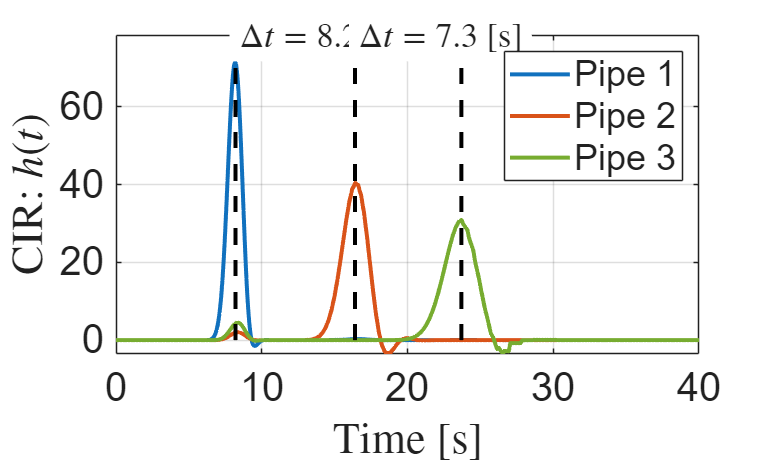

plot([tau_1_COMSOL tau_1_COMSOL],[0 1.1*max_intensity],'--k',LineWidth=2)
plot([tau_2_COMSOL tau_2_COMSOL],[0 1.1*max_intensity],'--k',LineWidth=2)
plot([tau_3_COMSOL tau_3_COMSOL],[0 1.1*max_intensity],'--k',LineWidth=2)

text(tau_1_COMSOL,1.1*max_intensity,strcat('$\Delta t=',num2str(tau_2_COMSOL-tau_1_COMSOL),'$ [s]'),Interpreter='latex',FontSize=fontsize-3,BackgroundColor='w')
text(tau_2_COMSOL,1.1*max_intensity,strcat('$\Delta t=',num2str(tau_3_COMSOL-tau_2_COMSOL),'$ [s]'),Interpreter='latex',FontSize=fontsize-3,BackgroundColor='w')


xlabel("Time [s]",'Interpreter','latex');
ylabel("CIR: $h(t)$",'Interpreter','latex');
set(gca,'FontSize',fontsize);
legend([p1,p2,p3],{'Pipe 1','Pipe 2','Pipe 3'},'Location','northeast');

figure; % Plotting the concentration with time
plot(timeVector, averageIntensities_swap_pipe_1, 'LineWidth', 2); hold on; % Plot average intensities with blue line and circle markers
plot(timeVector, averageIntensities_swap_pipe_2, 'LineWidth', 2); % Plot average intensities with blue line and circle markers
plot(timeVector, averageIntensities_swap_pipe_3, 'LineWidth', 2); % Plot average intensities with blue line and circle markers

p1=plot(time+,h_cir_1_COMSOL,'-','LineWidth',2,'MarkerIndices',1:10:length(conc_Pipe_1_COMSOL));grid on; hold on;
% plot(tau_1,peak_1,'o','LineWidth',2,'Color','black',MarkerFaceColor='black');
p2=plot(time,h_cir_2_COMSOL,'--','LineWidth',2,'MarkerIndices',1:10:length(conc_Pipe_1_COMSOL),'Color',"#D95319");
% plot(tau_2,peak_2,'o','LineWidth',2,'Color','black',MarkerFaceColor='black');
p3=plot(time,h_cir_3_COMSOL,'-o','LineWidth',2,'MarkerIndices',1:10:length(conc_Pipe_1_COMSOL),'Color',"#77AC30");
% plot(tau_3,peak_3,'o','LineWidth',2,'Color','black',MarkerFaceColor='black');

#### Flow rate for a given pressure drop  

**Description:** This block assumes a syringe is connected to the inlet of the pipe and introduces a constant flow rate Q. The pressure formula follows the Hagen–Poiseuille equation [1, Eq. (3.1) and Table 3.1 pp. 43]

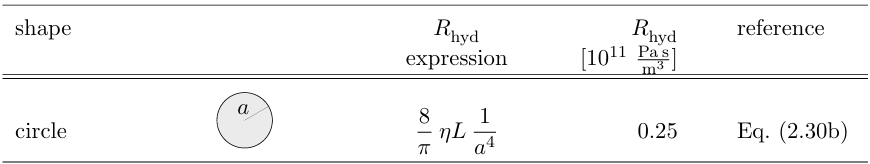

$\Delta P=RQ
$, (1)

where $R$ denotes the pipe resistance and is given as follows

- Rectangular cross-shape $R=\frac{12\mu L}{1-0.63\frac{h}{w}}\cdot\frac{1}{h^3w}$, $w\gg h$

- Circular cross-shape $R=\frac{8\mu L}{\pi r^4}$

where 

$\mu$ is the water viscosity,

$L$ is the channel length,

$r$ is the radius of a circular pipe.

$h$ is the height of a rectangular pipe

$w$ is the width of a rectangular pipe

### Flow

% %flow rate in [uL/min], achievable in 0.5-7 ul/min as in [4]
% Q_uL_m=2
% %flow rate in [m^3/s]
% Q_m3_s=Q_uL_m*(1e-6*1e-3)/60;

% Q_nL_per_min=10;
% Q=Q_nL_per_min*10^(-9)*10^(-3)/60;
% Delta_P=(8*mu_Water*L_outer)/(pi*radius_cylinder_1^4)*Q
% Delta_P_mmHg=Delta_P/133.322
%flow rate in [m^3/s]
% Q_m3_s=p0*(pi*r_vec.^4)/(8*mu*l_vec(end));
% %flow rate in [uL/min]
% Q_uL_m=Q_m3_s*60/(1e-6*1e-3);
% disp(['Min Q_ul_m=',num2str(min(Q_uL_m))])
% disp(['Max Q_ul_m=',num2str(max(Q_uL_m))])
% 
% %flow rate in [uL/h]
% Q_uL_h=Q_m3_s*60*60/(1e-6*1e-3);

% %Evaluating the reader volume and time to fill the volume
% r_Reader=500e-6/2;
% r_pipe=max(r_vec);
% delta_t_min=2*pi*r_Reader^2*r_pipe/max(Q_m3_s)
% delta_t_max=2*pi*r_Reader^2*r_pipe/min(Q_m3_s)


#### Length and width per pipe

%Pipe_1
%width
w_1=0;
[var,factor]=getVarTable(w_1,table);
w_1=eval(var{1})*factor

w_1 = 1.6767e-04

%heigth
height_pipe=0;
[var,factor]=getVarTable(height_pipe,table);
height_pipe=eval(var{1})*factor

height_pipe = 3.8000e-05

%Length
L_1=0;
[var,factor]=getVarTable(L_1,table);
L_1=eval(var{1})*factor

L_1 = 0.0177


%Pipe_2
%width
w_2=0;
[var,factor]=getVarTable(w_2,table);
w_2=eval(var{1})*factor

w_2 = 1.9489e-04

%Length
L_2=0;
[var,factor]=getVarTable(L_2,table);
L_2=eval(var{1})*factor

L_2 = 0.0252

%Angle
varphi_2=0;
[var,factor]=getVarTable(varphi_2,table);
varphi_2=eval(var{1})*factor

varphi_2 = 1.5907


%Pipe_3
%width
w_3=0;
[var,factor]=getVarTable(w_3,table);
w_3=eval(var{1})*factor

w_3 = 1.6737e-04

%Length
L_3=0;
[var,factor]=getVarTable(L_3,table);
L_3=eval(var{1})*factor

L_3 = 0.0305

%Angle
varphi_3=0;
[var,factor]=getVarTable(varphi_3,table);
varphi_3=eval(var{1})*factor

varphi_3 = 1.9077


%resistance of the rectangular Pipe 1
R_1=12*mu_Water*L_1/(1-0.63*height_pipe/w_1)*(1/(height_pipe^3*w_1))

R_1 = 2.6817e+13

%resistance of the rectangular Pipe 2
R_2=12*mu_Water*L_2/(1-0.63*height_pipe/w_2)*(1/(height_pipe^3*w_2))

R_2 = 3.2207e+13

%resistance of the rectangular Pipe 3
R_3=12*mu_Water*L_3/(1-0.63*height_pipe/w_3)*(1/(height_pipe^3*w_3))

R_3 = 4.6448e+13


%evaluating the extra hydraulic resistance
% Specify the MAT file for the parameters
% csvFileName = 'COMSOL_pipe_1_concentration_line_outlet.csv';
csvFileName = 'polygon_outer.csv';
%entry from the table
opts=detectImportOptions(csvFileName,'ReadVariableNames', false);
table=readtable(csvFileName,opts);
x_pol_outer=table.Var1;
y_pol_outer=table.Var2;

%evaluating the extra hydraulic resistance
% Specify the MAT file for the parameters
% csvFileName = 'COMSOL_pipe_1_concentration_line_outlet.csv';
csvFileName = 'polygon_upper.csv';
%entry from the table
opts=detectImportOptions(csvFileName,'ReadVariableNames', false);
table=readtable(csvFileName,opts);
x_pol_upper=table.Var1;
y_pol_upper=table.Var2;

%length of the inlet
L_in=x_pol_outer(2)-x_pol_outer(1) %inlet connection to Pipes 2 and 3

L_in = 2.1000e-04

w_in=2*abs(y_pol_upper(1)-y_pol_outer(10))

w_in = 3.6566e-04


%length of the outlet
L_out=x_pol_outer(5)-x_pol_outer(4)

L_out = 2.1000e-04

w_out=abs(y_pol_outer(6)-y_pol_outer(5))

w_out = 9.8995e-05


%inlet resistance to Pipes 2 and 3
R_in=12*mu_Water*L_in/(1-0.63*height_pipe/w_in)*(1/(height_pipe^3*w_in))

R_in = 1.3411e+11

%outlet resistance
R_out=12*mu_Water*L_out/(1-0.63*height_pipe/w_out)*(1/(height_pipe^3*w_out))

R_out = 6.1061e+11


% Equivalent parallel resistance
Req = 1 / sum(1 ./ [R_1 R_2 R_3])

Req = 1.1127e+13


%Flow to the pipe 1 in a single connection
Q_1=p0/(Req)*Req/R_1;
Q_1_uL_min=Q_1*6e10

Q_1_uL_min = 1.3424



%Flow to the pipe 2 in a single connection
Q_2=p0/(R_in+R_out+Req)*Req/R_2;
Q_2_uL_min=Q_2*6e10

Q_2_uL_min = 1.0477



%Flow to the pipe 2 in a single connection
Q_3=p0/(R_in+R_out+Req)*Req/R_3;
Q_3_uL_min=Q_3*6e10

Q_3_uL_min = 0.7264

#### Péclet condition

Pe_cond=zeros(length(w_vec),length(l_vec));

Q_min=inf;
Q_max=-inf;

for i_w=1:length(w_vec)

    %i_r/length(r_vec)*100

    for i_l=1:length(l_vec)

        %Hydraulic Resistance
        R=12*mu*l_vec(i_l)/(1-0.63*height_pipe/w_vec(i_w))*1/(height_pipe^3*w_vec(i_w));
        
        %Volumetric flow
        Q=p0/R;

        %Mean velocity
        %Circular channel of radius r_vec(i_r) [2, pag. 54]
        % v_char=r_vec(i_r)^2*p0/(3*mu*l_vec(i_l))
        %Rectangular channel of size w x h [1, below Eq. (3.40) pag. 53]
        v_char=Q/(w_vec(i_w)*height_pipe);

        %Peclet number, see [3, Eq. below 11] 
        Pe=v_char*height_pipe/D_coeff;

        %Evaluating the Effective Diffusion coefficient
        %Circular channel: [1, Eq.(4.54) pp.77]
        %D_eff=r_vec(i_w)^2*v_char^2/48/D_coeff;
        %Shallow rectangular channel, h<<w, see the constant 1/200 in [3,
        %Eq. (15)] and the formula for the diffusion coeff in [3, Eq. (1)].
        D_eff=D_coeff*(1+1/200*Pe^2);

        % %Péclet number, circular channel this evaluation follows [1,Eq. (4.44) pp.75]
        % Pe=r_vec(i_r)*v_char/D_coeff;
        
        %Validating the diffusion within the pipe
        %Diffusion occurred along the radial axis and x-axis
        if(Pe<4*l_vec(i_l)/height_pipe && Pe>1)
            Pe_cond(i_w,i_l)=1;

            if(Q<Q_min)
                Q_min=Q;
                Q_min_w_idx=i_w;
                Q_min_l_idx=i_l;
            end

            if(Q>Q_max)
                Q_max=Q;
                Q_max_w_idx=i_w;
                Q_max_l_idx=i_l;
            end

        %Diffusion hasn't occurred along the radial axis and x-axis
        elseif(Pe>4*l_vec(i_l)/height_pipe)
            Pe_cond(i_w,i_l)=0;
        
        %Diffusion hasn't occurred along the axis
        elseif (Pe<1)
            Pe_cond(i_w,i_l)=-1;
        end
    end
end

disp(['Q_min=',num2str(Q_min*6e10),' uL/min'])

Q_min=0.85804 uL/min


disp(['Q_max=',num2str(Q_max*6e10),' uL/min'])

Q_max=5.442 uL/min


## Plotting the Pe_cond matrix

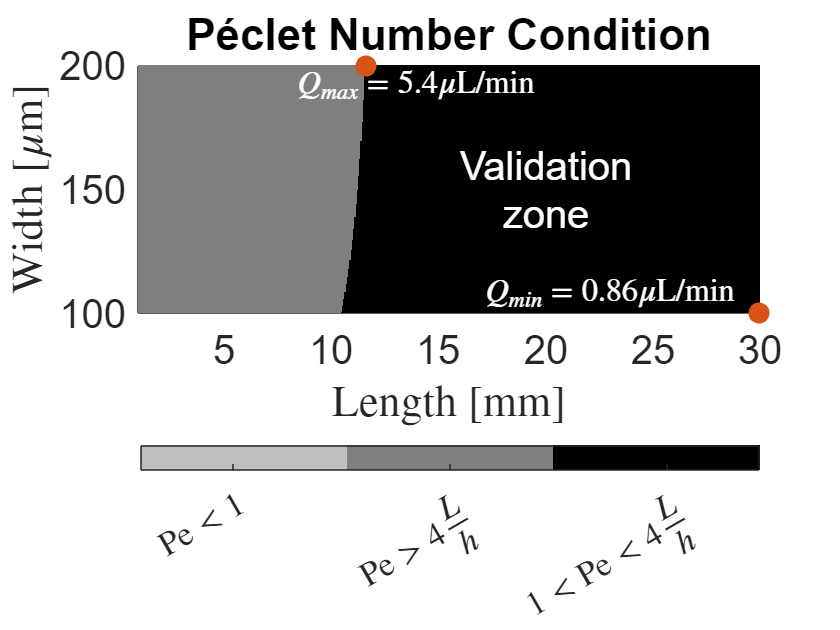

figure;

% Plot for all conditions in a single plot
hold on;
imagesc(l_vec*1e3, w_vec*1e6, Pe_cond); hold on
% colormap([0.8500 0.3250 0.0980; 0.9290 0.6940 0.1250; 0.0072 0.4470 0.7410]); % Colors for 0, -1, and 1
colormap([0.75, 0.75, 0.75; 0.5, 0.5, 0.5; 0, 0, 0]); % Colors for 0, -1, and 1
caxis([-1 1]); % Set color axis limits to match Pe_cond values

text(20,150,{'Validation', 'zone'},'FontSize',fontsize,'Color','w','HorizontalAlignment','center');

text(l_vec(Q_min_l_idx-120)*1e3,w_vec(Q_min_w_idx+40)*1e6,{strcat('$Q_{min}=',num2str(Q_min*6e10,2),' \mu$L/min')},'FontSize',fontsize-4,'Color','w','HorizontalAlignment','center',Interpreter='latex');
text(l_vec(Q_max_l_idx+40)*1e3,w_vec(Q_max_w_idx-40)*1e6,{strcat('$Q_{max}=',num2str(Q_max*6e10,2),' \mu$L/min')},'FontSize',fontsize-4,'Color','w','HorizontalAlignment','center',Interpreter='latex');

plot(l_vec(Q_min_l_idx)*1e3, w_vec(Q_min_w_idx)*1e6,'o','Color',"#D95319",MarkerFaceColor="#D95319",MarkerSize=10);
plot(l_vec(Q_max_l_idx)*1e3, w_vec(Q_max_w_idx)*1e6,'o','Color',"#D95319",MarkerFaceColor="#D95319",MarkerSize=10);


% Create a colorbar and set its ticks and labels
cb = colorbar('Ticks', [-0.7, 0, 0.7], 'TickLabels', {'$\mathrm{Pe}<1$', '$\mathrm{Pe}>4\frac{L}{h}$', '$1<\mathrm{Pe}<4\frac{L}{h}$'}, 'TickLabelInterpreter', 'latex', 'FontSize', fontsize-3,'Location','southoutside');
% cb.Layout.Tile='south';

% Set the color of the colorbar with transparency
%set(colorbarHandle, 'alpha', 0.5); % RGBA format, where A is the alpha value
%alpha(0.5);

xlabel('Length [mm]','Interpreter','latex');
ylabel('Width [$\mu$m]','Interpreter','latex');
axis([l_vec(1)*1e3 l_vec(end)*1e3 w_vec(1)*1e6 w_vec(end)*1e6])
set(gca, 'YDir', 'normal');
title('Péclet Number Condition');
set(gca,'FontSize',fontsize ,'YDir', 'normal'); % To display the y-axis in the correct direction
hold off;

### Peak time and peak amplitude vs width and length

% Q_min=inf;
% Q_max=-inf;
% 
% syms t
% 
% %length of the pipe
% total_points=1e2;
% w_vec=linspace(100e-6,200e-6,total_points);%selected based on the mixer dimenssion in [4, Fig. 3]
% l_vec=linspace(12,30,total_points)*1e-3;%selected based on the Peclet number condition
% 
% %defining the time interval
% total_points_time=1e2;
% t_ini=1e-7;
% t_end=10;
% t_vector = linspace(t_ini,t_end,total_points_time);
% time_sampling=t_vector(2)-t_vector(1);
% 
% h_amp=zeros(length(w_vec),length(l_vec));
% h_tau=zeros(length(w_vec),length(l_vec));
% 
% for i_w=1:length(w_vec)
% 
%     i_w/length(w_vec)*100
% 
%     for i_l=1:length(l_vec)
% 
%         %Hydraulic Resistance
%         R=12*mu*l_vec(i_l)/(1-0.63*height_pipe/w_vec(i_w))*1/(height_pipe^3*w_vec(i_w));
% 
%         %Volumetric flow
%         Q=p0/5/R;
% 
%         %Mean velocity
%         %Circular channel of radius r_vec(i_r) [2, pag. 54]
%         % v_char=r_vec(i_r)^2*p0/(3*mu*l_vec(i_l))
%         %Rectangular channel of size w x h [1, below Eq. (3.40) pag. 53]
%         v_char=Q/(w_vec(i_w)*height_pipe);
% 
%         %Peclet number, see [3, Eq. below 11] 
%         Pe=v_char*height_pipe/D_coeff;
% 
%         %Evaluating the Effective Diffusion coefficient
%         %Circular channel: [1, Eq.(4.54) pp.77]
%         %D_eff=r_vec(i_w)^2*v_char^2/48/D_coeff;
%         %Shallow rectangular channel, h<<w, see the constant 1/200 in [3,
%         %Eq. (15)] and the formula for the diffusion coeff in [3, Eq. (1)].
%         D_eff=D_coeff*(1+1/200*Pe^2);      
% 
%         %Validating the diffusion within the pipe
%         %Diffusion occurred along the radial axis and x-axis
%         if(Pe<4*l_vec(i_l)/height_pipe && Pe>1)
%             %Evaluating the concentration of the straigth channel
%             c=1./2.*erfc((l_vec(i_l)-v_char*t)./(2*sqrt(D_eff*t)));
%             %Evaluating the channel impulse response
%             h=diff(c,t);
%             %for validation purposes only
%             % figure;
%             % figure;plot(t_vector,subs(h,t_vector)); grid on;
%             h_vs_t=subs(h,t_vector);
%             [h_amp(i_w,i_l),idx]=max(h_vs_t);
%             h_tau(i_w,i_l)=t_vector(idx);
%             %Fiding the peak of the channel ımpulse response
% 
%             if(Q<Q_min)
%                 Q_min=Q;
%                 Q_min_w_idx=i_w;
%                 Q_min_l_idx=i_l;
%             end
% 
%             if(Q>Q_max)
%                 Q_max=Q;
%                 Q_max_w_idx=i_w;
%                 Q_max_l_idx=i_l;
%             end
% 
%         %Diffusion hasn't occurred along the radial axis and x-axis
%         elseif(Pe>4*l_vec(i_l)/height_pipe)
%             disp(['Concentration is not constant along the x-axis, Pe=',num2str(double(Pe)),' is larger than ',num2str(4*l_vec(i_l)/height_pipe)])
%             i_l
%             i_r
% 
% 
%         %Diffusion hasn't occurred along the axis
%         elseif (Pe<1)
%             disp(['Diffusion hasn''t occurred along the axis, Pe=',num2str(double(Pe)),' is less than ',num2str(sqrt(48))])
%             i_l
%             i_r
% 
%         end
%     end
% end

### Phase 2

%Pipe 1

ans = 1

ans = 2

ans = 3

ans = 4

ans = 5

ans = 6

ans = 7.0000

ans = 8

ans = 9

ans = 10

ans = 11

ans = 12

ans = 13

ans = 14.0000

ans = 15

% Specify the MAT file for the parameters
csvFileName = '3D_Pipe_1_Outlet_Concentration_Surface_Average_Phase_2.csv';
%entry from the table
opts=detectImportOptions(csvFileName,'ReadVariableNames', false);
% preview(csvFileName,opts) %data file preview
table=readtable(csvFileName,opts);
time=table.Var1;
%concentration
conc_Pipe_1_COMSOL=table.Var2;
%CIR
h_cir_1_COMSOL=gradient(conc_Pipe_1_COMSOL,time);

%Pipe 2
% Specify the MAT file for the parameters
% csvFileName = 'COMSOL_pipe_1_concentration_line_outlet.csv';
csvFileName = '3D_Pipe_2_Outlet_Concentration_Surface_Average_Phase_2.csv';
%entry from the table
opts=detectImportOptions(csvFileName,'ReadVariableNames', false);
% preview(csvFileName,opts) %data file preview
table=readtable(csvFileName,opts);
time=table.Var1;
%concentration
conc_Pipe_2_COMSOL=table.Var2;
%CIR
h_cir_2_COMSOL=gradient(conc_Pipe_2_COMSOL,time);

%Pipe 3
% Specify the MAT file for the parameters
% csvFileName = 'COMSOL_pipe_1_concentration_line_outlet.csv';
csvFileName = '3D_Pipe_3_Outlet_Concentration_Surface_Average_Phase_2.csv';
%entry from the table
opts=detectImportOptions(csvFileName,'ReadVariableNames', false);
% preview(csvFileName,opts) %data file preview
table=readtable(csvFileName,opts);
time=table.Var1;
%concentration
conc_Pipe_3_COMSOL=table.Var2;
%CIR
h_cir_3_COMSOL=gradient(conc_Pipe_3_COMSOL,time);


figure;
p1=plot(time,h_cir_1_COMSOL,'-','LineWidth',2,'MarkerIndices',1:10:length(conc_Pipe_1_COMSOL));grid on; hold on;
plot(tau_1,peak_1,'o','LineWidth',2,'Color','black',MarkerFaceColor='black');
p2=plot(time,h_cir_2_COMSOL,'--','LineWidth',2,'MarkerIndices',1:10:length(conc_Pipe_1_COMSOL),'Color',"#D95319");
plot(tau_2,peak_2,'o','LineWidth',2,'Color','black',MarkerFaceColor='black');
p3=plot(time,h_cir_3_COMSOL,'-o','LineWidth',2,'MarkerIndices',1:10:length(conc_Pipe_1_COMSOL),'Color',"#77AC30");
plot(tau_3,peak_3,'o','LineWidth',2,'Color','black',MarkerFaceColor='black');
xlabel("Time [s]",'Interpreter','latex');
ylabel("CIR: $h(t)$",'Interpreter','latex');
set(gca,'FontSize',fontsize);
legend([p1,p2,p3],{'Pipe 1','Pipe 2','Pipe 3'},'Location','northeast');

#### For validation purposes

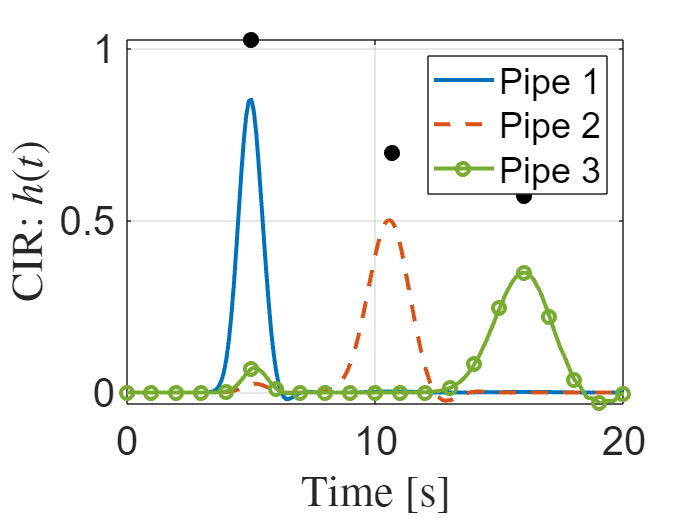

i_l=30;
i_w=1;
syms t
%Hydraulic Resistance
R=12*mu*l_vec(i_l)/(1-0.63*height_pipe/w_vec(i_w))*1/(height_pipe^3*w_vec(i_w));


%Volumetric flow
Q=p0/R;

%Mean velocity
%Circular channel of radius r_vec(i_r) [2, pag. 54]
% v_char=r_vec(i_r)^2*p0/(3*mu*l_vec(i_l))
%Rectangular channel of size w x h [1, below Eq. (3.40) pag. 53]
v_char=Q/(w_vec(i_w)*height_pipe);

%Peclet number, see [3, Eq. below 11]
Pe=v_char*height_pipe/D_coeff;

%Evaluating the Effective Diffusion coefficient
%Circular channel: [1, Eq.(4.54) pp.77]
%D_eff=r_vec(i_w)^2*v_char^2/48/D_coeff;
%Shallow rectangular channel, h<<w, see the constant 1/200 in [3,
%Eq. (15)] and the formula for the diffusion coeff in [3, Eq. (1)].
D_eff=D_coeff*(1+1/200*Pe^2);

%Evaluating the concentration of the straigth channel
c=1./2.*erfc((l_vec(i_l)-v_char*t)./(2*sqrt(D_eff*t)));
%Evaluating the channel impulse response
h=diff(c,t);
h_vs_t=subs(h,t_vector);
%for validation purposes only


%defining the time interval
total_points_time=1e3;
t_ini=1e-7;
t_end=2;
t_vector = linspace(t_ini,t_end,total_points_time);
time_sampling=t_vector(2)-t_vector(1);

%finding the maximum
tau_1=l_vec(i_l)/v_char-2*D_eff/v_char^2;
[~,idx]=min(abs(t_vector-tau_1));
peak_1=h_vs_t(idx);

figure;
plot(t_vector,h_vs_t,'LineWidth',2); grid on; hold on;
plot(tau_1,peak_1,'o','LineWidth',2); grid on; hold on;

xlabel('Time [s]','Interpreter','latex');
ylabel ('$h_1(t)$','Interpreter','latex');
%axis([tau_1/10 4*tau_1 0 2])
set(gca,'FontSize',fontsize);

h_vs_t=subs(h,t_vector);
[h_amp(i_w,i_l),idx]=max(h_vs_t);
h_tau(i_w,i_l)=t_vector(idx);



% Plotting the surface for the peak_tau matrix
figure;
s=surf(l_vec*1e3, w_vec*1e6, h_tau);hold on
s.EdgeColor = 'none';
xlabel('Length [mm]','Interpreter','latex');
ylabel('Width [$\mu$m]','Interpreter','latex');
zlabel('Peak time $\tau$ [s]','Interpreter','latex');
title('Pipe 1')
%axis([l_vec(1)*1e3 l_vec*1e3 w_vec(1)*1e6 w_vec*1e6])
set(gca, 'YDir', 'normal');
set(gca,'FontSize',fontsize ,'YDir', 'normal'); % To display the y-axis in the correct direction

% Plotting the surface for the peak_tau matrix
figure;
s=surf(l_vec*1e3, w_vec*1e6, h_amp); hold on
s.EdgeColor = 'none';
xlabel('Length [mm]','Interpreter','latex');
ylabel('Width [$\mu$m]','Interpreter','latex');
zlabel('Peak amplitude','Interpreter','latex');
title('Pipe 1')
% axis([l_vec(1)*1e3 l_vec(col)*1e3 w_vec(1)*1e6 w_vec*1e6])
set(gca, 'YDir', 'normal');
set(gca,'FontSize',fontsize ,'YDir', 'normal'); % To display the y-axis in the correct direction
view(-40, 51); % Adjust the view angle for better visualization

% Superposing the tau_coords on the plot
plot3(l_vec(tau_coords(:,2))*1e3, w_vec(tau_coords(:,1))*1e6, tau_coords(:,4), 'o-',...
    'MarkerSize', 12, 'Color','#D95319','MarkerFaceColor','#D95319');
hold off;

#### Peak time and peak amplitude vs width and length

%Loading results
% Ensure the dataset folder exists
outputFolder = 'dataset';
if ~exist(outputFolder, 'dir')
    mkdir(outputFolder);
end

load(fullfile(outputFolder, 'tau_vs_r_l.mat'))


#### Synthesis of length and radius for a given tau_sample

% Given value of tau
tau_value = 3; % Replace 'tau' with the actual value if needed

% Finding the closest coordinates to tau, 2*tau, and 3*tau in the peak_tau matrix
tau_coords = zeros(3, 4); % Preallocate for coordinates

for k = 1:3
    target_value = k * tau_value;
    [row, col] = find(abs(peak_tau - target_value) == min(min(abs(peak_tau - target_value))));
    tau_coords(k, :) = [row, col, target_value, peak_amp(row,col)];
end

%find the coordinates where calculations are zero
[row, col] = find(peak_tau < peak_tau(end,1),1);
disp('Row coordinates where peak_tau is zero:');
disp(row);
disp('Column coordinates where peak_tau is zero:');
disp(col);


if isempty(col)
    [~,col]=size(peak_tau);
end

col=50
% Plotting the surface for the peak_tau matrix
figure;
s=surf(l_vec(1:col)*1e3, w_vec(1:col)*1e6, peak_tau(1:col,1:col));hold on
s.EdgeColor = 'none';
xlabel('Length [mm]','Interpreter','latex');
ylabel('Width [$\mu$m]','Interpreter','latex');
zlabel('Peak time $\tau$ [s]','Interpreter','latex');
axis([l_vec(1)*1e3 l_vec(col)*1e3 w_vec(1)*1e6 w_vec(col)*1e6])
set(gca, 'YDir', 'normal');
set(gca,'FontSize',fontsize ,'YDir', 'normal'); % To display the y-axis in the correct direction

view(-40, 51); % Adjust the view angle for better visualization

% Superposing the tau_coords on the plot
plot3(l_vec(tau_coords(:,2))*1e3, w_vec(tau_coords(:,1))*1e6, tau_coords(:,3), 'o-',...
    'MarkerSize', 12, 'Color','#D95319','MarkerFaceColor','#D95319');
hold off;

% Plotting the surface for the peak_tau matrix
figure;
s=surf(l_vec(1:col)*1e3, w_vec(1:col)*1e6, peak_amp(1:col,1:col)); hold on
s.EdgeColor = 'none';
xlabel('Length [mm]','Interpreter','latex');
ylabel('Width [$\mu$m]','Interpreter','latex');
zlabel('Peak amplitude','Interpreter','latex');
axis([l_vec(1)*1e3 l_vec(col)*1e3 w_vec(1)*1e6 w_vec(col)*1e6])
set(gca, 'YDir', 'normal');
set(gca,'FontSize',fontsize ,'YDir', 'normal'); % To display the y-axis in the correct direction
view(-40, 51); % Adjust the view angle for better visualization

% Superposing the tau_coords on the plot
plot3(l_vec(tau_coords(:,2))*1e3, w_vec(tau_coords(:,1))*1e6, tau_coords(:,4), 'o-',...
    'MarkerSize', 12, 'Color','#D95319','MarkerFaceColor','#D95319');
hold off;

% Finding the derivative of the peak_tau matrix with respect to the length and radius
[rows, cols] = size(peak_tau);
peak_tau_derivative = zeros(rows, cols);

for i = 1:col
    for j = 1:col
        if i > 1
            dL = l_vec(i) - l_vec(i-1);
            peak_tau_derivative(i, j) = (peak_tau(i, j) - peak_tau(i-1, j)) / dL;
        end
        if j > 1
            dR = r_vec(j) - r_vec(j-1);
            peak_tau_derivative(i, j) = (peak_tau(i, j) - peak_tau(i, j-1)) / dR;
        end
    end
end

% % Displaying the derivative matrix
% disp('Derivative of peak_tau matrix:');
% disp(peak_tau_derivative);

% Plotting the derivative of the peak_tau matrix
figure;
s = surf(l_vec(2:col)*1e3, r_vec(2:col)*1e3, peak_tau_derivative(2:col, 2:col)); hold on;
s.EdgeColor = 'none';
xlabel('Length [mm]','Interpreter','latex');
ylabel('Radius [mm]','Interpreter','latex');
zlabel('$\tau''$','Interpreter','latex');
axis([l_vec(1)*1e3 l_vec(col)*1e3 r_vec(1)*1e3 r_vec(col)*1e3])
set(gca, 'YDir', 'normal');
set(gca,'FontSize',fontsize ,'YDir', 'normal'); % To display the y-axis in the correct direction
view(-40, 51); % Adjust the view angle for better visualization
hold on;


### Results for Pipe 1

%Loading results
% Ensure the dataset folder exists
outputFolder = 'dataset';
if ~exist(outputFolder, 'dir')
    mkdir(outputFolder);
end

load(fullfile(outputFolder, 'pipe_1_w_vs_l.mat'))

idx=find(w_vs_l_pipe_1~=0);
figure;
plot(l_vec(idx)*1e3,w_vs_l_pipe_1(idx)*1e6,'LineWidth',2); grid on;
xlabel('Length pipe 1 ($L_1$) [mm]','Interpreter','latex');
ylabel ('Radius pipe 1 ($r_1$) $\mu$m]','Interpreter','latex');
set(gca,'FontSize',fontsize);

syms t
%Validation of time and peak amplitude sampling
peak_amp_pipe_1=zeros(1,length(idx));

% figure;

for i=1:length(idx)
    L_1=l_vec(idx(i));
    w_1=w_vs_l_pipe_1(idx(i));

    %Rectangular channel of size w x h [1, below Eq. (3.40) pag. 53]
    v_char=Q_m3_s/(w_1*height_pipe);

    %Peclet number, see [3, Eq. below 11] 
    Pe=v_char*height_pipe/D_coeff;

    %Evaluating the Effective Diffusion coefficient
    %Shallow rectangular channel, h<<w, see the constant 1/200 in [3,
    %Eq. (15)] and the formula for the diffusion coeff in [3, Eq. (1)].
    D_eff=D_coeff*(1+1/200*Pe^2);

    %Evaluating the concentration of the straigth channel
    c=1./2.*erfc((L_1-v_char*t)./(2*sqrt(D_eff*t)));
    %Evaluating the channel impulse response
    h=diff(c,t);
    % for validation purposes only
    % fplot(h,[tau_1/10 3*tau_1]); grid on; hold on;

    %
    peak_amp_pipe_1(i)=subs(h,t,tau_1);
end

% xlabel('Time [s]','Interpreter','latex');
% ylabel ('Straigth pipe 1 $h_1(t)$','Interpreter','latex');
% set(gca,'FontSize',fontsize);

figure;
%% colecting the amplitude
plot(l_vec(idx)*1e3,peak_amp_pipe_1,'LineWidth',2);grid on;
xlabel('Length pipe 1 ($L_1$) [mm]','Interpreter','latex');
ylabel ('max $h_1(t)$','Interpreter','latex');
set(gca,'FontSize',fontsize);

### Plotting $h_1(t)$

figure;

target_1=50*1e-3;
target_2=100*1e-3;
target_3=150*1e-3;

[~, idx_1] = min(abs(l_vec(idx) - target_1));  % idx is index of closest value
[~, idx_2] = min(abs(l_vec(idx) - target_2));  % idx is index of closest value
[~, idx_3] = min(abs(l_vec(idx) - target_3));  % idx is index of closest value


samples=[idx_1,idx_2,idx_3];

legend_text=cell(1,length(samples));
m=1; %index for the legend
for i=samples
    L_1=l_vec(idx(i));
    w_1=w_vs_l_pipe_1(idx(i));

    %mean velocity
    %Rectangular channel of size w x h [1, below Eq. (3.40) pag. 53]
    v_char=Q_m3_s/(w_1*height_pipe);

    %Peclet number, see [3, Eq. below 11] 
    Pe=v_char*height_pipe/D_coeff;

    %Evaluating the Effective Diffusion coefficient
    %Shallow rectangular channel, h<<w, see the constant 1/200 in [3,
    %Eq. (15)] and the formula for the diffusion coeff in [3, Eq. (1)].
    D_eff=D_coeff*(1+1/200*Pe^2);

    %Evaluating the concentration of the straigth channel
    c=1./2.*erfc((L_1-v_char*t)./(2*sqrt(D_eff*t)));
    % Evaluating the channel impulse response
    h=diff(c,t);

    fplot(h,[tau_1/10 4*tau_1],'LineWidth',2); grid on; hold on;

    %legend on the plot
    legend_text{m}=strcat('$r_1=',num2str(w_1*1e6,3),'$ [$\mu$m] $L_1=',num2str(L_1*1e3,3),'$ [mm]');
    m=m+1;
    
end

legend({legend_text{:}},...
    'Location','northwest','NumColumns',1,'Interpreter',"latex",'FontSize',fontsize);%

xlabel('Time [s]','Interpreter','latex');
ylabel ('$h_1(t)$','Interpreter','latex');
axis([tau_1/10 4*tau_1 0 2])
set(gca,'FontSize',fontsize);


#### Evaluating the approximate time to fill in the reader

%Evaluating the reader volume and time to fill the volume
r_Reader=500e-6/2;
r_pipe=51.2e-6;%solution from the h1(t) plot
l_pipe=51.3e-3;%solution from the h1(t) plot

reader_delay=2*pi*r_Reader^2*r_pipe/Q_m3_s

%Evaluating the CNN delay
v_char=r_pipe^2*p0/(3*mu*l_pipe);
%CNN_delay=l_pipe/v_char

reader_delay/tau_sample*100

### Results Pipe 2

%Loading results
% Ensure the dataset folder exists
outputFolder = 'dataset';
if ~exist(outputFolder, 'dir')
    mkdir(outputFolder);
end

load(fullfile(outputFolder, 'pipe_2_w_vs_varphi.mat'))

idx=find(w_vs_varphi_pipe_2~=0);

figure;
plot(varphi_vec(idx),w_vs_varphi_pipe_2(idx)*1e6,'LineWidth',2); grid on;
xlabel('Turning angle ($\varphi$) [rad]','Interpreter','latex');
ylabel ('Radius pipe 2 ($r_2$) [$\mu$m]','Interpreter','latex');
set(gca,'FontSize',fontsize);

%Validation
%Evaluating the channel impulse response
%Matlab code to evaluate the integral
syms t x w rd v varphi D C_0
% Define the substitution for x
z = (x - v*t + varphi*rd) / (2*sqrt(D*t));
% Define the integrand
integrand = 1/2*C_0*erfc(z);
% Perform the symbolic integration from r = 0 to r = dr
I = simplify(1/(w)*int(integrand, rd, 0, w));
%Performing the integral
c_avg=1/(w)*int(integrand,rd);
%evaluating the integral limits between rd=0 and rd=2r
c_avg_int=subs(c_avg,[rd,C_0],[w,1])-subs(c_avg,[rd,C_0],[0,1]);

peak_amp_pipe_2=zeros(1,length(idx));
for i=1:length(idx)
    L_2=L_1/sin((pi-varphi)/2);

    %Rectangular channel of size w x h [1, below Eq. (3.40) pag. 53]
    v_char=Q_m3_s/(w*height_pipe);

    %Peclet number, see [3, Eq. below 11] 
    Pe=v_char*height_pipe/D_coeff;

    %Evaluating the Effective Diffusion coefficient
    %Shallow rectangular channel, h<<w, see the constant 1/200 in [3,
    %Eq. (15)] and the formula for the diffusion coeff in [3, Eq. (1)].
    D_eff=D_coeff*(1+1/200*Pe^2);

    c_avg_param_int=subs(c_avg_int,[x,D,v],[L_2,D_eff,v_char]);

    %evaluating the channel impulse response
    h_turn=diff(c_avg_param_int,t);
    peak_amp_pipe_2(i)=subs(h_turn,[t,w,varphi],[2*tau_1,w_vs_varphi_pipe_2(idx(i)),varphi_vec(idx(i))]);
end

xlabel('Time [s]','Interpreter','latex');
ylabel ('Radius pipe 2 ($r_2$)','Interpreter','latex');
set(gca,'FontSize',fontsize);

figure;
%% colecting the amplitude
plot(subs(L_1/sin((pi-varphi)/2),varphi,varphi_vec(idx))*1e3,peak_amp_pipe_2,'LineWidth',2);grid on;
xlabel('Length pipe 2 ($L_2$) [mm]','Interpreter','latex');
ylabel ('max $h_2(t)$','Interpreter','latex');
set(gca,'FontSize',fontsize);


### Plotting $h_2(t)$

%Validation
%Evaluating the channel impulse response
%Matlab code to evaluate the integral
syms t x w rd v varphi D C_0
% Define the substitution for x
z = (x - v*t + varphi*rd) / (2*sqrt(D*t));
% Define the integrand
integrand = 1/2*C_0*erfc(z);
% Perform the symbolic integration from r = 0 to r = dr
I = simplify(1/(w)*int(integrand, rd, 0, w));
%Performing the integral
c_avg=1/(w)*int(integrand,rd);
%evaluating the integral limits between rd=0 and rd=2r
c_avg_int=subs(c_avg,[rd,C_0],[w,1])-subs(c_avg,[rd,C_0],[0,1]);

samples=[1,round(length(idx)/2),length(idx)];
legend_text=cell(1,length(samples));
m=1;
figure;
peak_amp_pipe_2=zeros(1,length(idx));
for i=samples
    L_2=L_1/sin((pi-varphi)/2);

    %Rectangular channel of size w x h [1, below Eq. (3.40) pag. 53]
    v_char=Q_m3_s/(w*height_pipe);

    %Peclet number, see [3, Eq. below 11] 
    Pe=v_char*height_pipe/D_coeff;

    %Evaluating the Effective Diffusion coefficient
    %Shallow rectangular channel, h<<w, see the constant 1/200 in [3,
    %Eq. (15)] and the formula for the diffusion coeff in [3, Eq. (1)].
    D_eff=D_coeff*(1+1/200*Pe^2);

    c_avg_param_int=subs(c_avg_int,[x,D,v],[L_2,D_eff,v_char]);

    %evaluating the channel impulse response
    h_turn=diff(c_avg_param_int,t);
    w_2=w_vs_varphi_pipe_2(idx(i));
    L_2_val=double(subs(L_2,varphi,varphi_vec(idx(i))));
    fplot(subs(h_turn,[w,varphi],[w_2,varphi_vec(idx(i))]),[tau_1/10 4*tau_1],'LineWidth',2); grid on; hold on;
    
    %legend on the plot
    legend_text{m}=strcat('$w_2=',num2str(w_2*1e6,3),'$ [$\mu$m] $L_2=',num2str(L_2_val*1e3,3),'$ [mm]');
    m=m+1;
    
end

legend({legend_text{:}},...
    'Location','northwest','NumColumns',1,'Interpreter',"latex",'FontSize',fontsize);%

axis([tau_1/10 4*tau_1 0 2])

xlabel('Time [s]','Interpreter','latex');
ylabel ('$h_2(t)$','Interpreter','latex');
set(gca,'FontSize',fontsize);

### Results Pipe 3

%Loading results
% Ensure the dataset folder exists
outputFolder = 'dataset';
if ~exist(outputFolder, 'dir')
    mkdir(outputFolder);
end

load(fullfile(outputFolder, 'pipe_3_w_vs_varphi.mat'))

idx=find(w_vs_varphi_pipe_3~=0);

figure;
plot(varphi_vec(idx),w_vs_varphi_pipe_3(idx)*1e6,'LineWidth',2); grid on;
xlabel('Turning angle ($\varphi$) [rad]','Interpreter','latex');
ylabel ('Turning pipe radius $\mu$m]','Interpreter','latex');
set(gca,'FontSize',fontsize);

%Validation
%Evaluating the channel impulse response
%Matlab code to evaluate the integral
syms t x w rd v varphi D C_0
% Define the substitution for x
z = (x - v*t + varphi*rd) / (2*sqrt(D*t));
% Define the integrand
integrand = 1/2*C_0*erfc(z);
% Perform the symbolic integration from r = 0 to r = dr
I = simplify(1/(w)*int(integrand, rd, 0, w));
%Performing the integral
c_avg=1/(w)*int(integrand,rd);
%evaluating the integral limits between rd=0 and rd=2r
c_avg_int=subs(c_avg,[rd,C_0],[w,1])-subs(c_avg,[rd,C_0],[0,1]);

% figure;
peak_amp_pipe_3=zeros(1,length(idx));
for i=1:length(idx)
    L_3=L_1/sin((pi-varphi)/2);

    %Rectangular channel of size w x h [1, below Eq. (3.40) pag. 53]
    v_char=Q_m3_s/(w*height_pipe);

    %Peclet number, see [3, Eq. below 11] 
    Pe=v_char*height_pipe/D_coeff;

    %Evaluating the Effective Diffusion coefficient
    %Shallow rectangular channel, h<<w, see the constant 1/200 in [3,
    %Eq. (15)] and the formula for the diffusion coeff in [3, Eq. (1)].
    D_eff=D_coeff*(1+1/200*Pe^2);

    c_avg_param_int=subs(c_avg_int,[x,D,v],[L_3,D_eff,v_char]);

    %evaluating the channel impulse response
    h_turn=diff(c_avg_param_int,t);
    % fplot(subs(h_turn,[r,varphi],[w_vs_varphi_pipe_2(idx(i)),varphi_vec(idx(i))]),[tau_1/10 3*tau_1]); grid on; hold on;

    peak_amp_pipe_3(i)=subs(h_turn,[t,w,varphi],[3*tau_1,w_vs_varphi_pipe_3(idx(i)),varphi_vec(idx(i))]);
end


figure;
%% colecting the amplitude
plot(subs(L_1/sin((pi-varphi)/2),varphi,varphi_vec(idx))*1e3,peak_amp_pipe_3,'LineWidth',2);grid on;
xlabel('Straight pipe 3 length ($L_3$) [mm]','Interpreter','latex');
ylabel ('max $h_3(t)$','Interpreter','latex');
set(gca,'FontSize',fontsize);

### Plotting $h_3(t)$

%Validation
%Evaluating the channel impulse response
%Matlab code to evaluate the integral
syms t x w rd v varphi D C_0
% Define the substitution for x
z = (x - v*t + varphi*rd) / (2*sqrt(D*t));
% Define the integrand
integrand = 1/2*C_0*erfc(z);
% Perform the symbolic integration from r = 0 to r = dr
I = simplify(1/(w)*int(integrand, rd, 0, w));
%Performing the integral
c_avg=1/(w)*int(integrand,rd);
%evaluating the integral limits between rd=0 and rd=2r
c_avg_int=subs(c_avg,[rd,C_0],[w,1])-subs(c_avg,[rd,C_0],[0,1]);

samples=[1,round(length(idx)/2),length(idx)];
legend_text=cell(1,length(samples));
m=1;
figure;
peak_amp_pipe_2=zeros(1,length(idx));
for i=samples
    L_3=L_1/sin((pi-varphi)/2);

    %Rectangular channel of size w x h [1, below Eq. (3.40) pag. 53]
    v_char=Q_m3_s/(w*height_pipe);

    %Peclet number, see [3, Eq. below 11] 
    Pe=v_char*height_pipe/D_coeff;

    %Evaluating the Effective Diffusion coefficient
    %Shallow rectangular channel, h<<w, see the constant 1/200 in [3,
    %Eq. (15)] and the formula for the diffusion coeff in [3, Eq. (1)].
    D_eff=D_coeff*(1+1/200*Pe^2);

    c_avg_param_int=subs(c_avg_int,[x,D,v],[L_3,D_eff,v_char]);

    %evaluating the channel impulse response
    h_turn=diff(c_avg_param_int,t);
    w_3=w_vs_varphi_pipe_3(idx(i));
    L_3_val=double(subs(L_3,varphi,varphi_vec(idx(i))));
    fplot(subs(h_turn,[w,varphi],[w_3,varphi_vec(idx(i))]),[tau_1/10 4*tau_1],'LineWidth',2); grid on; hold on;
    
    %legend on the plot
    legend_text{m}=strcat('$w_3=',num2str(w_3*1e6,3),'$ [$\mu$m] $L_3=',num2str(L_3_val*1e3,3),'$ [mm]');
    m=m+1;
    
end

legend({legend_text{:}},...
    'Location','northwest','NumColumns',1,'Interpreter',"latex",'FontSize',fontsize);%

axis([tau_1/10 4*tau_1 0 2])

xlabel('Time [s]','Interpreter','latex');
ylabel ('$h_3(t)$','Interpreter','latex');
set(gca,'FontSize',fontsize);

#### Peak time and peak amplitude vs radius and length

% operating on the permisible range
total_points=20;
r_vec=linspace(50,60,total_points)*1e-6;%radius cilinder
l_vec=linspace(12,100,total_points)*1e-3;%length of the pipe

%defining the time interval
total_points=1e3;
time_ini=1e-7;
time_end=300;
time_vector = linspace(time_ini,time_end,total_points);

syms t

peak_amp=zeros(length(r_vec),length(l_vec));
peak_tau=zeros(length(r_vec),length(l_vec));

for i_w=1:length(r_vec)

    i_w/length(r_vec)*100

    for i_l=1:length(l_vec)

        %Evaluating the mean velocity [2, pag. 54]
        v_char=r_vec(i_w)^2*p0/(3*mu*l_vec(i_l));

        %Evaluating the Effective Diffusion
        %[1, Eq.(4.54) pp.77]
        D_eff=r_vec(i_w)^2*v_char^2/48/D_coeff;

        %Validating the diffusion within the pipe
        %Evaluation of the Péclet number, this evaluation follows [1,Eq. (4.44) pp.75]
        Pe=r_vec(i_w)*v_char/D_coeff;

        if(Pe>4*l_vec(i_l)/r_vec(i_w))            
            disp(['Concentration is not constant along the x-axis, Pe=',num2str(Pe),' is larger than ',num2str(4*l_vec(i_l)/r_vec(i_w))])
            i_l
            i_w
        end

        if(Pe<sqrt(48))            
            disp(['Diffusion hasn''t occurred along the axis, Pe=',num2str(Pe),' is less than ',num2str(sqrt(48))])
            i_l
            i_w
        end

        %Evaluating the concentration of the straigth channel
        c=1./2.*erfc((l_vec(i_l)-v_char*t)./(2*sqrt(D_eff*t)));
        %Evaluating the channel impulse response
        h=diff(c,t);

        % %for testing purposes only
        % figure;plot(time_vector,subs(h,time_vector)); grid on;

        %Looking for the maximum of the channel impulse response with the first derivative
        h_diff=diff(h,t);
        %Evaluating the derivative with time
        obj_fcn_time=double(subs(h_diff, t, time_vector));

        % %for testing purposes
        % figure;plot(time_vector,obj_fcn_time);

        %Evaluating the time interval where the first derivative is zero
        [~, max_time] = max(obj_fcn_time);
        [~, min_time] = min(obj_fcn_time);
        
        % %for testing purposes
        % time_vector(max_time)
        % time_vector(min_time)
        
        %looking for the peak time and peak amplitude
        peak_tau(i_w,i_l)=vpasolve(h_diff,t,[time_vector(max_time),time_vector(min_time)]);
        peak_amp(i_w,i_l)=subs(h, t, peak_tau(i_w,i_l));
    end
end

%Saving results
% Ensure the dataset folder exists
outputFolder = 'dataset';
if ~exist(outputFolder, 'dir')
    mkdir(outputFolder);
end

% Save the results into the specified folder
save(fullfile(outputFolder, 'tau_vs_r_l.mat') ,'peak_tau','peak_amp','p0','mu', 'time_vector','l_vec','r_vec');

% %Loading results
% % Ensure the dataset folder exists
% outputFolder = 'dataset';
% if ~exist(outputFolder, 'dir')
%     mkdir(outputFolder);
% end
% 
% load(fullfile(outputFolder, 'tau_vs_r_l.mat'))

% Plotting the surface for the peak_tau matrix
figure;
s=surf(l_vec*1e3, r_vec*1e6, peak_tau);
s.EdgeColor = 'none';
xlabel('Length [mm]','Interpreter','latex');
ylabel('Radius [$\mu$m]','Interpreter','latex');
zlabel('Peak time $\tau$ [s]','Interpreter','latex');
axis([l_vec(1)*1e3 l_vec(end)*1e3 r_vec(1)*1e6 r_vec(end)*1e6])
set(gca, 'YDir', 'normal');
set(gca,'FontSize',fontsize ,'YDir', 'normal'); % To display the y-axis in the correct direction
hold off;

view(-40, 51); % Adjust the view angle for better visualization

% Plotting the surface for the peak_tau matrix
figure;
s=surf(l_vec*1e3, r_vec*1e6, peak_amp);
s.EdgeColor = 'none';
xlabel('Length [mm]','Interpreter','latex');
ylabel('Radius [$\mu$m]','Interpreter','latex');
zlabel('Peak amplitude','Interpreter','latex');
axis([l_vec(1)*1e3 l_vec(end)*1e3 r_vec(1)*1e6 r_vec(end)*1e6])
set(gca, 'YDir', 'normal');
set(gca,'FontSize',fontsize ,'YDir', 'normal'); % To display the y-axis in the correct direction
hold off;
view(-40, 51); % Adjust the view angle for better visualization

function addingPathParentFolderByName(targetName)
    % Start from the current directory
    currFolder = pwd;
    found = false;
    
    % Continue searching until you reach the root folder
    while true
        % Get the parent folder
        [parentFolder, currentName] = fileparts(currFolder);
        
        % Check if the current folder's name is the target
        if strcmpi(currentName, targetName)
            found = true;
            break;
        end
        
        % If we've reached the root or no change, exit the loop
        if isempty(parentFolder) || strcmp(currFolder, parentFolder)
            break;
        end
        
        % Move one level up
        currFolder = parentFolder;
    end

    if found
        addpath(genpath(currFolder));
        fprintf('Adding matlab path to: %s\n', currFolder);
    else
        error('Folder named "%s" not found in any parent directory.', targetName);
    end
end

function [value,factor]= getVarTable(var,table)
%This function extract the value of the variable specified in the entry var within
%the table specified in entry table

varName = inputname(1);

%find the corresponding entry within the table of parameters
for i=1:numel(table(:,1))
    entry_str=strcmp(table{i,1},varName);
    if entry_str
        entry_table=i;
        break
    end
end

%validating
if isempty(entry_table)
    error('Table has no column named "%s".', varName);
    value=NaN;
    factor=NaN;
else
    %reading the value in the second column of the table
    str=table{entry_table,2};
    if(isempty(findstr(str{1},'[')))
        value=table{entry_table,2};
    else
        value=extractBefore(table{entry_table,2},'[');
    end
    %reading the units of the value within the second column in the table
    unit = extractBetween(table{entry_table,2}, "[", "]"); % e.g. ["um"; "mm"; "nm"; "m"]
    if isempty(unit)
        factor=1;
    else
        %Define your conversion map to meters
        convMap = containers.Map( ...
            {'nm','um','mm','cm','m','km','rad','s','ms','us','ns','Pa','mmHg','m/s','mol/m^3','mol/L','m^2/s','cm^2/s','g/mol'}, ...
            [1e-9,1e-6,1e-3,1e-2,1,1e3,1,1,1e-3,1e-6,1e-9,1,133.322,1,1,1e3,1,1e-4,1e-3] );
        %Finding the conversion factors
        if isKey(convMap, unit)
            factor = convMap(unit{1});
        else
            error('Unit "%s" not recognized.', unit{1});
        end
    end

end
end

function varName = getVarName(var)
%This function extract the value of the variable specified in var within
%the table specified in table

% getVarName   Extract the name of the workspace variable
varName = inputname(1);
end


## References

[1] H. Bruus, *Theoretical Microfluidics*. 2008. doi: [10.1093/oso/9780199235087.001.0001](https://doi.org/10.1093/oso/9780199235087.001.0001).  

[2] Howard C. Berg. 1993. Random Walks in Biology. Princeton University Press.

[3] M. L. Parks and L. A. Romero, “Taylor–Aris dispersion in high aspect ratio columns of nearly rectangular cross section,” *Mathematical and Computer Modelling*, vol. 46, no. 5, pp. 699–717, Sep. 2007, doi: [10.1016/j.mcm.2006.11.029](https://doi.org/10.1016/j.mcm.2006.11.029).  